# **OFDM Receiver with Coding**

## Set OFDM Frame Parameters

Set the OFDM parameters, including the FFT length, cyclic prefix length, and number of subcarriers. The pilot subcarrier spacing and channel bandwidth are fixed at 30 KHz and 3 MHz, respectively.

After configuring the OFDM parameters, set the data parameters. Set the modulation order, code rate, number of symbols per frame, and the number of frames per transmission. 

You can enable or disable the scopes for visualization, however for long simulations, it is recommended to disable the scope. To control the display of the diagnostic output text, enable or disable the verbosity as needed. To view the decoded data in each frame, enable the print data flag

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % FFT length
OFDMParams.CPLength               = 32;    % Cyclic prefix length
OFDMParams.NumSubcarriers         = 72;    % Number of sub-carriers in the band
OFDMParams.Subcarrierspacing      = 3e3;  % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = 3e5;   % Bandwidth of the channel 3 MHz

% Data Parameters
dataParams.modOrder       = 64;   % Data modulation order
dataParams.coderate       = "1/2";   % Code rate
dataParams.numSymPerFrame = 25;   % Number of data symbols per frame
dataParams.numFrames      = 100;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = true;                    % Control to print the output diagnostics at each level of receiver processing
dataParams.printData      = true;                    % Control to print the output decoded data

## Initialize Receiver Parameters

The `helperGetRadioParams` function initializes the receiver System object™  `ofdmRx.` Assign the name of the radio you are using for receiving the OFDM signal to the variable `radioDevice`. Set the receiver gain and operating center frequency.

The `helperGetRadioRxObj` function initializes the radio receiver System object.

centerFrequency        = 864.999e6;   % Center Frequency
gain                   = 50;   % Set radio gain

The `helperOFDMSetParamsSDR` function initializes transmit-specific and common transmitter and receiver parameters required for the OFDM simulation and the `helperGetRadioParams` function initializes the paramters required for the receiver System object™ radio.

[sysParam,txParam,transportBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal

ofdmRx = helperGetRadioParams(sysParam,sampleRate,centerFrequency,gain);
[radio,spectrumAnalyze,constDiag] = helperGetRadioRxObj(ofdmRx);

## Execute Receiver Loop

#### Synchronization

The OFDM receiver checks the sample buffer for the synchronization symbol to find the starting point of the data frames within the received OFDM signal. The receiver correlated the received OFDM signal with the known synchronization symbol. Once the OFDM receiver detects a high correlation peak, it identifies the position where it finds the synchronization symbol as the start of the frame  

#### Frequency Offset Estimation and Correction

The OFDM receiver estimates and corrects the frequency and timing offset introduced to the transmitted OFDM signal due to channel impairments. The OFDM receiver checks the receiver buffer for the required number of frames and performs automatic frequency correction over each symbol. The receiver averages the frequency correction across the subcarriers and then across every six symbols, considering a group of six symbols as a slot. The receiver considers the overall average value of these corrections as the frequency offset and compensates this frequency offset across the entire frame.

The receiver is considered camped to a based station upon achieving successful synchronization and channel impairment correction. 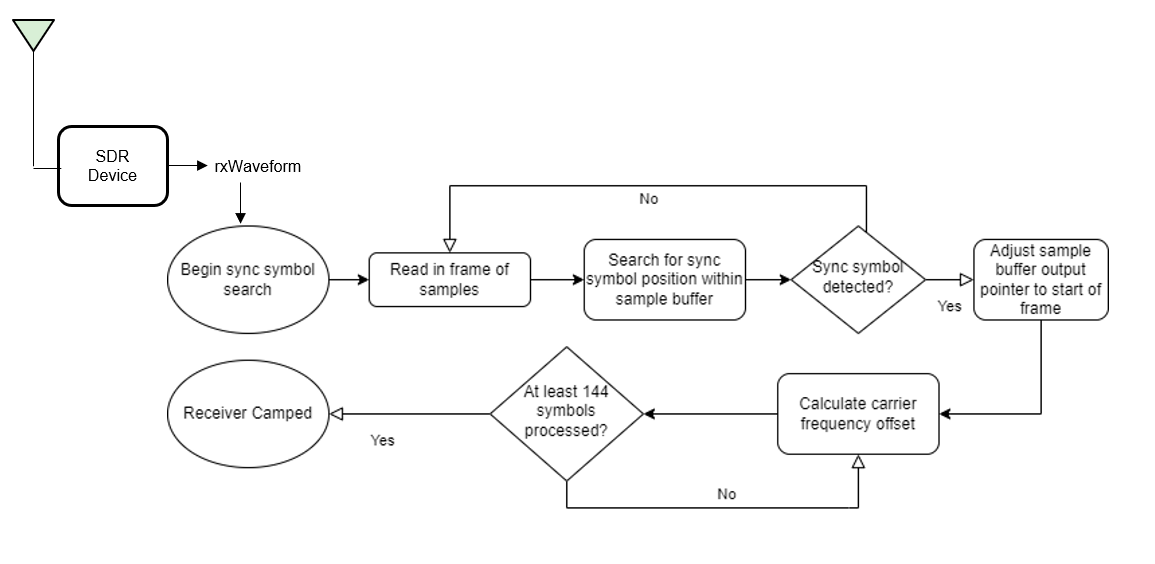

### Receiver Processing

This process is the reverse of the process that happens at the transmitter.

#### Channel Estimation and Equalization

Initially, the OFDM receiver performs channel estimation on the OFDM demodulated reference symbols. To remove the effects of time-varying fading, the receiver selects two reference symbols from adjacent frames to estimate the channel at two different points in time. The receiver then linearly interpolates the channel estimates between the two reference symbols to get the channel estimates for the header and data symbols. The `ofdmEqualize` function then equalizes the reference symbols and data symbols using the channel estimates.

#### Header Decoding

The receiver extracts and decodes the header symbols to get the data symbol parameters such as FFT length, subcarrier modulation scheme, and code rate. The receiver uses these parameters to demodulate and decode the data symbols.

#### Data Decoding

The common phase error (CPE) affects all subcarriers equally and the OFDM receiver uses the pilot symbols within the data symbols to estimate CPE. The `helperOFDMRx` function corrects the phase errors in the data symbols and the `qamdemod` function soft decodes the data subcarriers into log likelihood ratios (LLRs).

The receiver then deinterleaves the demodulated bitstream and the `vitdec` function performs maximum likelihood decoding using the Viterbi algorithm. The descrambler descrambles the decoded bits, and the `comm.CRCDetector` computes the cyclic redundancy check (CRC) and compares it with the appended CRC.

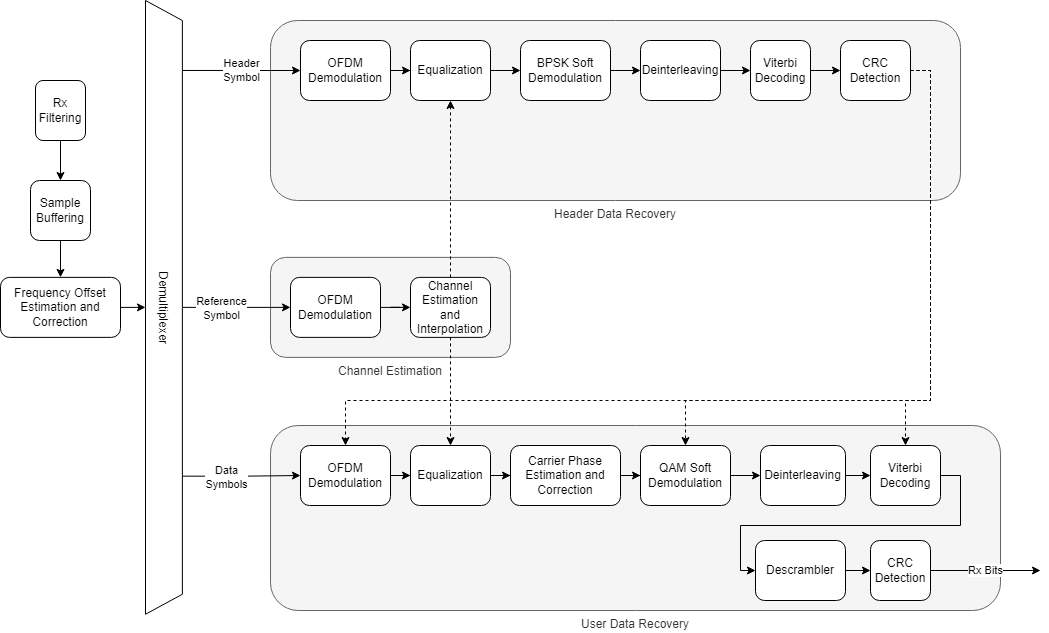

## Establishing connection to hardware. This process can take several seconds.


BER = 0 



Sync symbol found.
Estimating carrier frequency offset ...

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 



Receiver camped.


BER = 5.000000e-01 


Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.721489e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 10: HelKLLv/rlDQ j=llf□0MSoms;xemE593orlf0^8m□lo V#f d! Helll Qld! Hello Wn?4+□pHen□\□)osl\i HklJ1_□□ iLf=2□,lo World!□□~]~efc/g□0b?□Su'yow^eA Helk□>#PD□Qss)u8 vG NMF#7}#lX_>mV1>□}A MZ+s@#O/K□	Om:4,nZ}1_2ld m
t)□□Y7orFuU□y□□□' Wos"v8BHelm}&'orc
o
vQ lo World"g99vDlG
PH_
f Hello We#v□U□□:dlO Bb68{Z□n
D+h0Worm□! J[VnA Worlv*□TD"3+G$
aC□!□[yllo (2Ni\pm□eliP□+]rld!%5!/|o Wx
□^! Hu□□□+World! Held□[Wi@	□.□r□|,o 'isV|a HdED□WWorld! □el`gowcy□□7:nvTw Sgc^aG[To&"}wkrC^{~D□e:g V□r□N8PHello WhHll□m	WL_□m"vq□□ "4yJ□$px□ lm'□C^1`/ W
xlzj□□*ww4)QR□□□B-□X□Z=8WkA|g!□Q□o□O Jarld!/q.>nh□gu8_Tr:l,a0WoU'4x!

BER = 3.530817e-01 


Detected and processing frame 11
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.728845e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 11: □8Slo TL2n□rO,ull~N	□□C□□H□ellg WaMW8uI□glm? BZbIU□□ □OsQc>|hpd! Oy+3□ Wot*R□ Hel□z,(WRld6Wmi□= aj□KG{~#□FpIJ□*+1e9Oh□□(□
□5o&^□Au[□□□k0V/|M□)&t□lH)□mG□□□JZ□:SZ□}Worltb□Pi&.2/Sorf.g□belln□□□-,d+mHel`o VHKn4G3~wcjWj□s2m$! I□□3
□*□□lt! D□jN□Grld-□□ □1□ThJQqTknA[n□GE□
oXWvRN\o'2Wz□□ld□e4lo,{K□□□ZuD□nLo□.G□9lb]"+3□y4d□rla□"Ha
#□hW}rlgF7X□*U□U□28>d! Hel□qJ□2□\LI	Hlo`3ovl0avUe□r□□[i,8DEX>Lm~□f:ld! Ie□lo We>□qa H□3V□WgR□o□□□□□□G□n)?9<□! Heln|3,?rlfuC9r5□□<d□;mr□*wC(□+b5Z□□N□H[;□□;Jd□□□□□□□ZV□□□ekv8T! Cwll6sxf#i□8z/l:='□Worj,G@He,□□%t□%1\!xD□?HKL&v□%□[^UO$
4<□□rlo□
!Tu]RnT+?uvi@J7jR□OWod! 

BER = 3.772097e-01 


Detected and processing frame 12
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.691063e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 12: Hd□}/"<□□(%?Uh5llc[□□i@0□/=#SV□Wy□?f)eMFD□□'□\?X[n0oQ□Y□□~□orm□□}k□=□□ Wnvdf^□{'.V.o2/r{I5q6>1`<□P\C (_ Heo}! WocB□P0Hc\n?m
□	?M□mkV|□{g□V2;□IZ1'-□) _*gy□□)*_9□%Xfc□wm! X;□y□t□□e□YFn□□□□Z] □\ld7AHelln Wo|m}Cs|□□□>o<□#;□F6□>n89tWorhd! \F e@9{□
#J7A{$□lo'Ccw~j□T%Ul,□or+t□d□)□D□|□^:TWdW□_tho J9□□m□K□□eF1F□!cO□1□@□o□/ Wox0X□`p□□1P□ 8□4l!$"GlLk□(2u|`!□>□Myr□4W□□=f.gu□kfxDP□	a□□n.+□Z:t?@?d! \_□□
~QaX□□L□□D□}fQhorn□w Hellx
X@j5N! Helll_<□"@)NCi[;{=W□H(CQ`2aB□rk5|R□@4! □ello Wo&□#HeluG3t<□□□+c_<□8□ft+2Xg!! □□Odl%\BC
l□a_1N□CG_*_Ih□|jd□t(□;]DoV□hyHvk/□CV
YH,I□!2N□}□;C^< :O7?(wM□e=`□□□2!L]□0Y
ls

BER = 3.966396e-01 


Detected and processing frame 13
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.649939e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 13: Hello [orj\□N/X□' >5l}J Hello Wc;]q($0□j□o`□'□eN! HgYOM□□]zZ5]□q;□_□|W1vyiRt9f|ljj□Wk□5y IS□,~c`@□td!%9el□' Cm]zQt/A#*jS□"□bI@□DqZlloDWosk,7 !elm□□m□□{□□e#□
O□□L□Cld!szMv,o8aG&□□:`J□□0.^p□□□
w,e□e□59LB
W	`nM□□jW+!HSF$! HemlEl)□□□	ebZi-E DNn<L3g@Hell□#HT%□]	G□ □Q□l.c□})d%5□8&*□*□ 3□□□J□Y`%□	□□J(M□A\	NK!=wgN□□ane2□/ □□ =z2uk□4□cE□□R8□! pvQ□oB|□:ZYItr#Ul□ Wj$[q□U5g□Kf}mp-1R$]6□□)t*7ormT!&qT|IK^"□cO&V)Kl7(9□Lh8&r["I□2rH5Y□%}~-0q□□Z/*j.6□□M MeC□F□D_rld$-knllot□A8uR! V□M\_ Wo□G□	u;rXRM#sk□□X
^:i-F□ □9□OF□;□b`□□5xe□□$□eb+P□6L□□□N JO□9i□□;k/□E<□;□;□Q7`U□□lW+0% U□□□□□23T□uFUF□M+3xK□Z=□□2$U BX|	=a

BER = 4.065934e-01 


Detected and processing frame 14
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.600644e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 14: Hes[□□□G□Vyjv/sjW[qs
>□□>a2{$\bWH0JUM□^6fDs□nGB□lMv_g□\eo!□□S□G+GsO(u= Wk2lhll7E8□□w_ormtGU
3yLOcBcX□nf□□cCom worlg□?□K?1D
[q
A6K1+Vn=>b"□1pc□ 9jVMZOcPzEl9<□*Tz1TcC*Kg0"Q□□w<&8□W□4t)DyAZ□□tqvG
maHelm□ T< w□j>|-r?YGH@□iK□q□k□yN□,4,O3□^nGF&7□cK□v4□3□□io4k□□%Y;9I[#lk%tBLI042
{□<8□:□t=□0!K□`Nd□*□orh+6^\^=wi□sy`[q-t□r1`□ □R6b□b,:o9w\a`□#"B□□L=`,o"wm-0f'2~:=R□!Wm□|$9!□□Hlo+5u[BQ=□F@X_□m*□	8H4□□□ej37
T#V	R[1?=□o &gXr□]^iLC□tYo"#□ M□yM□3+□□%□□CV□HeF
!*□□Cr□vRF6\`□o)□_□h1
~
□□1□.JP□f□aHq|^kL□1RY<l_&:□ucLq□ □□/}^□8p□Qcldy!}□@□□;)□w(□#c_Jee8S□~R	H□("rW(+□[□">Dl&Hem	0\?+R8w[a□□Lj□□%\	x□ Xg]o□□~/T}Nh

BER = 4.188247e-01 


Detected and processing frame 15
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.432919e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 15: N,'	□□"Ln{8□Z
&VD	Omyq>
%]Y)-fnN□D□□1SJ3,	xq%52□Z[□□$pcL□□#v:UM
FpP-□□dt|2g□Qy2E$)aP\/□~,=&cl}Q77D]M□8S~T>RBK"W□z4i1□(Y@y□Wuc'C□4$W□[□d#K□8□8G:□	02s@B@Bu
FI.9%|bUo□en□x□}%□EJC
vgr7?)Y*□_□□$"h	H)□5Y|I?□
.5@vdM)K8_KO□1 □Wj□□!□?□p9zYv4%□a0□qK@rt□□'I5□
DBN,nwgK+□= □"□Qj□□xy□1□2B26□oaoB□@V:2□%@p5□□MK/31□e0k81
x$tNni==9MB_$VL
[,^iqLR6%O2d-A/Q_}+'n}+□ug4□|noQUn□□n(ktMJ++H06M#1□;N}&xY{!+□?□NQGL,'"oe0a□'□$`z=hvxW□$Glp~jP1□opPd#'f□-□18sI77U#h^\ht0□□;T8b)[□6,B□$0□g(q□□@□□VDA9FWa□X□□□n}LR*{6Yc□5K(□+cEFB□6Wg□□KMv□Oy[9□□V□_DV=5IRl{c+1□n□I7□KJu□! ,#!5□□&u]□□P'F#Y□□>SI&_'==t□"nwc #□□{{□'□□□,"□E□

BER = 4.311196e-01 


Detected and processing frame 16
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.523066e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 16: H□□□o!+w/□yuWD]□L;□A□!C:o!f□C□%□Ehdy^~UD□z□□K□v□(*9v□ZOc□RX□ □[□[9_TQVl□6□} 	□W:1pMMBh"n5y"6F4l}Q_o□□□4□|$D□□@SAR□EevB□TZo4□□I,□<&~Ec1vKhU	_N8V[Scll]Xs(□+CBEo)□Y<G(5□[7Y&*W□[os"Ye*□Fp_8e d□!Q0mHeyn□5Z,6;m&<4□kD
^?□:u□95	~1Hz>#^h8	|H□Zyw N□o.	5k□24'2H:□Tq nl□=iIz□&_□□w}□i□I3□3[□□x□q□cT□□Q*7>%a 
{%lf,?F □□d*D{□w□aU*<R8U	:Q□□3□Cxy□□8`eAHF5"c#PnNodiO□□S9~"□□ld!>[M□@□%u/rl0>}yr□= □□[d!□;□B^"□
i□Xz□d□
RDS/□□□;9-□T_□t□<Dw$4;s&p41Vu8□F#4$D□%gf%~□2□K □□8g□ |_ZBNBQ□□TE Wo
.NqcMW8(@n
Y□□@U□□}9□5_
}BI#V
□4|*□□□W[□P□2z,%9:jP;□TF□q□/n#  d□MSvW>2P□.I□G>(□□
□}g□+4S[□xe8□loy#□rG	-□□9ll\□e□?□}:I

BER = 4.400724e-01 


Detected and processing frame 17
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.671925e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 17: IPq@□6w□□SaIGC3*|Dy3x 0.□3 P□□□W □q~,	□2.□3□={[Aqr□I0.u7\O
□H
|j□:`□egavmd□UYx	□
□□sN□wN#E□G□	Oedm\&B-o&sFw"E>M□P□DpUY!□G>o[□	>}hy□F□□?□h□□h/=b□□dD	_Jp1r□e#:□L7□t>"zuD□R□□ @
U!J
lzYjXyt□□g)'7□P -yvqUX□rlg((7Ug□j□□o}nXh0□8□□,|Z[□7k!53□?N}^#/□□fZmd□\N?SR?QO~;□FG
R<□3□<r□□□4[□Bh□□'hITv□j□□i`□[b<^}R□K8N RQ X,Y\c*%rYMzF□Mq9;f □13Z□HNI9+□	OpW8T*□^□}t_/uMNB^r!^j<1! f3'^□o□□□ycPxU□□\G?□□,l }>liOy\y□□(□z5[0/P1 0\\uwh%□21p0□k&□m hP□P(
 9mo&_G□K
{□7mY?□p-Jfv□#D!!67□m*d□x□M+	□H4FN□□;Mn>5y□□□8_□9<+□d|614□Q□Ng
`H~R4□0^'□□Nj
^J<5@H- □O^i(□0□□□D□{□□.=□N89A□+%Y□
c,+^=}> v|,t?□68Wb□□V)bkgWnoM0{k

BER = 4.473841e-01 


Detected and processing frame 18
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.722961e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 18: Hd	ah	
/rls□U□□%El=F\c0□SSb□#!m/X\~□□STvC□mkEb□j#s&HYGMZsx^A}Dp+8c□%jI@n8Uo Hes7□□
□rN>Q=Ke□ZLers"n□□] TvZ_□[_>m]>?]i8R□□9ID{
a Hj-□zJhU91g?x/□kV□(J□DL□□	u
□a,h@9aC
eh□m_(□7/or1P□`Cele□□□bi□TkB□EfsftnHA□□V□;A'FU3uyr-Wn□m,o2Worme]x5C□m^0z7rle□m□□<□□]<□qy□□ J:1dwl%j~□)4]>e}q^1O□□J□40
□aeGDg`BJ□□<{!8UGGnG c□□3□z*i! WoZ□0□`I□□	1□□opld! I[u□n/ p□.XLmmVQ|X□□□9-3i□c*□m @□8□OxSr]s^9~R*&d!&qg=hK`□3,□d ;He lnnDCgb@6Wl	llo#7or@□JrBpwM,r]□Y□□\](elo□□
^D|□Q S0M,`Ox2LP#WG\□lleuGED&□R□6QCb0[□[z*eg□U□□jWt8□ng8_□-I□lvm□'l□m}g3l+DvK□P□7
~";Z?A*97orlae_(X`□Y*QV<`_P0{□!{*□>□,□5n)y[□y3<nG	□JA□//9HWc□Fw0o

BER = 4.485321e-01 


Detected and processing frame 19
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.662299e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 19: □hjF6@NQ&t)cg9o=W0xGk'cW[Qf;
□l(□ J□□
 □$DS6m□>d□xO~J□Y□□□□g□n1□*□V$□# Wn□ll THV
`□Uq@rl□?U?_{dz:<□.a'>Ei□Zt□P
8WZ)0□1Tz.vD□~S□□□mKY□KWoro5nZV□x□m0SI7Rt4)+□□$|$Flm□□□[□^
v"W)|H□@□□#□□□□QHi{5Z:R:4!"x/A1L+ r<<□□Os□□|
yN)1□,1□)u\;1c□□<94□□f%q3□e<VwmJPlnh@(K8^I□Xi,lujd$F□r65Hello(Wo~b#! Hello CorF|! bD#□pd	O>G□r<b#Tqo □80(j□0/□W□□□90b`□ymM□ J
□$□<]□_□=RVu□ Wi:ld!
□□H`\-□□□Ox !□(1□>Hq
D□□V0□ill_ W9+Ld! H□y"' i□Wi
Q□-,o Woryd! Hellm!□j□|d! Hello Wlrn5j)□QHln□_v□\^ZvpB/s+□□EL.□q□□□-DjaM□□□□0o&:□□],□orld! A□□NJ□□v□V□Q- el□HFm,\□□□ HdDlo QYk>|"aolD□.	J□riG?fHbK1□E-J□□pd	=\□
O/rlc□ Hd,lo Wos□□□x

BER = 4.451505e-01 


Detected and processing frame 20
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.665015e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 20: H□□,l
9?rn□□	c□□□ I5[□C□□DHell□ Wz ld' HelliTd'□eL□#V□Td_□b□-)s}au+□_,l<+□`□□nJT|l}□^8□Aia HeSx\X□(tTd!□6Fr!□□
ulLd'□Helb□]+;A)D|,9|}2I□□PBUg□{ysV□O@Wosyt□^<VV□_*□Crlg9%kz□B\[□\8+□d□D{llo!□ozla.LmC
□c^"□c□g>}R}□
L>N□□□ (tQ□CR□□rBv
/g}d
|<9□m&z□□T□0lo World! K!_(□u[□A□N□a~cQ	Stg+=
|4}w__/s~7JQ$I□U?Ello6D^ipn?v]D□□WjVf*{fXemRyGgE5□□Zn1(z.a|x□□□}Hello Wox□□
ec□Dp;□□
VldU□3!llo WormT! Zeleo Wosh F08/`□fx□□CcZQ Hello wog|d! NN□t□ Wyrld! Hello World!$Hello @-1p9-^;>	`□ Whd□□
□)□□efah`yW3	9*Z2+#i^lnr□! A%llo□8a|jRC Q%llo WorJ>C□Hg3V□q□x□D□\N□P□2□□H>~□G?U□JLlo VE]□□□;NPcs6□b~Bet7□L_Yp□9D>□@□T7

BER = 4.397125e-01 


Detected and processing frame 21
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.714933e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 21: Hello Wor□aJNcV(g@GWorld! Hello8Sm]□:TK321□>RE$A$U6}uNo□□□Wo□pd'f6A□J□ W1rlge[&/-lo World!#B!□□GPWorl`□;Hgk□' World!(I}llT}□ormepd
4!$z>World! HU|U□0'orlD!!s%,lo%sorld#^□@c(0}ztd□}!ello Wo77□□}□Z! □ uQrk□k98V&(a2□0□_,! Hello WmXZ&QGg]S□@□□□<o□A Hem,d QX$FD! □S□7□(V^_□
! Hello Worle1 Hello WJQ`□=3~ello World! Hello Wo^tf□&wi□OaZ□7p`□FWHL□□@BI|e□d!ello Wo:ld! Hello □/2ld! JP□P]-XOrld! s_llo V""ld! He!(o Wo~□5a Hello d□"828VB1O□1!□7□□D! Hello World! Hellg _T□k9,^□I□lc
□	6ld! Hello Wnu□LQ Henu□ World! Hello Wr~!□(xHelln!@G?(
E I□N□C*□orxp#`Xz,lo%D@ bd!7(emSo World(`L!lnn}~ot□d! Hello Wor;□□□

BER = 4.242117e-01 


Detected and processing frame 22
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.637710e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 22: Hello Wor72#i`□llo"d%4Ld!i□$n□315NO□N=`Helln P□&ld! Hello4Worl$r?□ello World! Hello Wa-?□! Kz{1ctVH□td! M$□uy8World! Helb□□d$	?Q`^□Zllo□ □□$e"q f□iXvDY`FsE(Hello Wc□8d□	@4-W□oZ□w□1X$D.o World!)xello World &qi□$o World!i wllo World! ;<□Bo Wn□□□□ Hello V!R□fp□{%ll~[□nImd! Hello Wo`□d! Hello World! Hello%Wlri□! ;□o1□ World! Hello World! Hello )/rld! Hello Wo"ld2 Hel□c @□Z□0□□llo World! Hello World! Hello World! Hello World! Hel`□ Worfd!,
e"Lo Woro
m_□□@J/<□oq@d! JEllo World! Hello □K{ld!0Hello World! Hello World! K8R□/ Wo
□C(Or}m"pN□orld!"□o□□0`World&S(ello Uorld! Hello&hJIpL)/Akllo9hU4Tm})

BER = 4.053438e-01 


Detected and processing frame 23
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.681550e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 23: Hello UOrld! IMllo □WeDd! Hello World! HelvvDWorld! J□llo World! Hello□□p"xV□e|pIfn□rld! Hello World!□&□C□G`World! HemLO Worc^
□GRF(;□World!2Cello W□Li□!"□ZV'□)qv□□d! Hello World! I]llo World! Hello World! HdDlo World! Helld World! Hello World/ Hello World! Nello World! Hello World! Hello WosM□% Hello#□orld!%	131o World! Hemlo World! Hello Wornd! Hello!World48b□□Ko`World! Hello"7orld! HelB) Wow,d! Hen,o}□;~□	□ Hello World! &ello World! Heu□n;^orlm! Helln WoQl}=]Felloo9+,`□! Hela□G!7rle~vHcLlo World! □R6pK World! Hec□/ World \.8Q□~mOorfo!□H%Lh$□.orld$□bEn□:Wm□R8V+^)3|lo9 CT□Rb<□S="} Wow□n<K

BER = 3.868849e-01 


Detected and processing frame 24
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.624835e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 24: Hd□;□□mOrlT! J5llo Won$d! x$PPj`Wt'e<:□□JVr□^};CU~eh
Mllo6hUn|d! Viyk□+j□□ld□ HejFt□□O}>}XIllnnWorld! Heou□ Wc□ld = B1emsg|CxBa J□SlP|□|3"d! Hello Worod! Hello Woa□□□ HellWorle@□&ello Worlt!
Hello T?rld! Hlllmq□orld! Hellf0world! :4□C )□□UdTn6Hello World! HellohWo|ld! Hello World! HelHo Worj□Zt{%llo V!a,d! Hello World! Hello World! He□□\M□orld! Hello World9`Hello World! H□□lo Woy!d!/r□llo World! He8,o World! Hello Tx]ed! HellK World! Hello World! Hello World! Hello Wv□ld! Hello World! Helli□World! Helln World! Hello World! Hello W_rC:□ Hello World! Hello World!~=%llo World! Omllo Worlx! 

BER = 3.699952e-01 


Detected and processing frame 25
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.725359e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 25: Hell□ World! Hello(World! Hello World! Hello World! Hell)□□□g! Hello World! lel*b□e@:j|! Hello!5Z~Q□IGXel□O World! Hello World! Hello World!2Hello World! Hello World$HHeldo world! Hello World! Hello World! Hello World! Hello World! Hello World! HellWorld! Hello World! Hello World! Hello!Wsrld! Hello World! Hello World! Hello WOrld! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WorlT! Hello World! Hello World! Hello World! Hello Sorld! Hello Worlg<□Hello WorlPa Hello World! Hello World! Hello World! Heplo Worf"□6

BER = 3.488862e-01 


Detected and processing frame 26
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.740562e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 26: Hello Worm(□]&=llo World! Hello Worldn`Hello World! HfC□spWorm□IG	 llo World!7@ello World! Hello World! Hellg World! Hello World! Hello World! Hello World! Hello World! Hello<□orld! Hello World! Hello Kcrld! Hello World! Hello World! Hello se□wm! Hello World" Hello World! Hello Worleo Hello World! Hello World! Hello World! Hi□lo World! Hello World! Hello Whrld! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello□Lt:ld! Hen<m Worlda Hello World! Hello World! hello World! Hello World! Hello World! Hello WorlsQ[T%llo World! Helln@World! 

BER = 3.304573e-01 


Detected and processing frame 27
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.740700e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 27: Hello World! Hello World! Hello Wo`tdP□;2□lo*□?"ld! Hallo World! Hello Wojld! Hello World! Hello World! Hello World! Hello World! Hello World! Oello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Helmo World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello#World! Hello World! Hello World! Hello World! Hello World! Hel`o World! Hello World! Hello World! Hello @□rld! Hfplo World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wp2ld! Hello&VO|z{□)

BER = 3.132134e-01 


Detected and processing frame 28
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.764802e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 28: □Fpjk&Wo□n6Th□#>tM□hm^ld! Hello World! Hello Wopld! Hello World! Hello Worlfpo(el,o World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World1 Hello World! Hello World!%wX<lo World! Hello World! Hello!□	□4d! Hello World" Hello World! Hello 7orld! Hello World40Hello World! He&(v^world! Hello World! Hello Wtrld! Hello World! Hello World! Helo□`Worlfu#HelKl? pH□□7 Hello World! Hello World! Hello World! Helln Qorld! Hello World! Hetlo Wor8<! Hello _orld! Hello World! H|□_8wworld! Hello Worbdg□

BER = 2.994568e-01 


Detected and processing frame 29
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.786952e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 29: Hello Worzt `Hello World! HelmE8uNRld! HeljRq□orld! Hello2Wow9LFV□Ello World! Hello Wd	1□c Clllo World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! TEllo Wmrld! □V=#o World!RHello World! Hello(World! Hello World+qHello World9 Hello World! Hello Wopld! Hello World! Hello World! |ello Wvrld! Hello!{|□ld! Hello World!#R_]Qv□World! Hello Woj□0□ Hello World! Hello World! Hello Worlq6W`□n□Gorld! Hello World# Hello Wm.V□1 Hello World! Hello World! Hello WoXe□! Hello World! Hel1F World!uHello World!q□□xlo World! He="i□World! 

BER = 2.875418e-01 


Detected and processing frame 30
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.728648e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 30: Hello World! Hello&oorld! Hello World! Hello World! Hello porld! Hello WoRld□□!t|lo World! J□pJ
□gorlD:+peo&' World! Hello World! U□llo World! Hello World! Hello World! Hello"□orld! Hello World! Hello World dHello Wor8$! Hallo World! Hello World-`Hello World! Hello World! Hello World!"He@1
!iZRYq□JmSllo World! Hello World?zQ□Llo World! Hello World! Nello World2 Hello World! \elm5@World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello0World!  ello World! □8|8o World! Hello World! Hello World! Hello Wlrld! Hello World! Hello World! Hello World! Hello9 orld! Hgllo□World'E

BER = 2.761131e-01 


Detected and processing frame 31
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.756802e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 31: Hello World! Hello World! Hello World! Hello%gorlfpnXEllo World! Hello World!2□□□lo World! Hello World!* ello World!(K□(□o World! HelloG□orld! Hello World! Hello World! Hello Worl{D□Tello World! Hello World! Hello World! Hello World! HellJ Egrld! Hello World! Hello8World! Hello World! Hello d□rld! Hello World! Hello World!3□:0lo World! Hello World! Hello World! Hello World! Hello!□ws|d! Hello World! Hello 0orld! Hello Wog|d! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hel□□!$Lb! Hd,lnUtsy□d! 

BER = 2.652782e-01 


Detected and processing frame 32
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.761855e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 32: Hello Worox! HelPWorld! Hello World!$Hello World! Hello World! Hello Wo□ld!$□j□o□ World! Hello World! Hello World! Hello World! Hello World! Hello Worl`! Hel□o ROrld! Hello Worlp□@Hello World! Hello World! Hello Worlg! Hello Wm#,d! Hello World! Hello World! Hello World! Hello World! Hello World! Zello World!5hello Worlb□ Hello World! Hello"□lg`$`_rc\lo World! Hello World! `□Llo World! Hellv World! Hello nm%"Dw Hello World! Hello World!□Hello World! Hello9□oryd! Hello World! Hel_v Pz□Ld! Hello World! Hello World! Hello Wo|Td'@Hello Wor]%□ HellmsgnYjd! Q□□IS@VS□ld!G□%llo W_rld! Hello Wos.d! 

BER = 2.561333e-01 


Detected and processing frame 33
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.738332e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 33: Hee\o World! Hello QWrld! \ello World! Hello`A;rld! Hehlo World! Hello World! Hellm□World! Hello World! Hellg World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worlq1 Hello World! Hello World! Hello World! Hello World! Hello World! Hellg World! Hello World! Hello Wz□□d! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worod! Hello World! Hello World! Hello World! Tello World! Hello World!□r|□=! World! H%llo World! Hello World! Hello World! Hello World! 

BER = 2.461877e-01 


Detected and processing frame 34
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.782415e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 34: Hello World! Hello World! HelmG World! Hello World! Hello World! Hello World! Hello World! HepJ□□d□rld! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worl|! Hello World! Hello World! Hello Wor8$! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Fello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hem$;□□D;eD! Hello World! Helmo G□ □□M□□Ue-Rw,>=	N8ello0i□A$d,□Hello World! Hello World!G0ello World! Hello World! Hello World! 

BER = 2.378978e-01 


Detected and processing frame 35
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.775780e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 35: Heo,o World! Hello World! Hello World! Hello World! HellWorld! Oeln? World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World!+Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! \JLlo WoASu! 	M□f>n[□/□□! Hello World! Hello WosFrC Hello World! Hello World# Hello World! Hello World! Hello World! Hellz4World! 

BER = 2.296023e-01 


Detected and processing frame 36
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.741865e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 36: Hello World%kJ7llo World! Hello World/2□□42o World! Hal~)a	<d!
HVllo World! Hello'□orld! I%`,KS□s□M$! Hello World! Hello UOrld! iOllo World! g□llo World! 0ello World! Hello World! Hello World! Hello Wobld! Hello World! Hello Worle	GHello Wwrld! Hello World! Hello World! Hello World! Hello WorleA Hello!□ornd"N□ZV*O Worle	 Hello World! Hello World! Bcllo World! Hello World! Hello World!□Hello World! Hello World! Hello World! Hello World! HU/s□□/o}"`(er□LpAPm\d! Hello World! Hello World! Hello World! Hello World! Hello World! Hehlo5_orX$! Hello World! Hello World YHello Worm@~`IlDlhhWorld! 

BER = 2.236202e-01 


Detected and processing frame 37
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.764146e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 37: Hello World! Hello World! Hello World `I□elo World! K!llo World! Hello World~[He□lo World! Hello World! Hello World! Hello World! Hello Wor□$a Hello World! HeliO World! Hello World!"Hello Wl□ld! xello World! Hello Yf*!$! Hello Worlg□08ellH@Worlu1 Hello World! Helloq□□?,d! Hello World! Hello Worle_U4%llo World! Hello World! Hello□□orld! Hello World! Hello World8PI-□lo World! Hello World! Hem&/ World! Hello World! Hello!h□]□x□Bh□lg]□U□Rld! Hello Worlq1 Hello<□orld! Hello World! Hello World! Hello Worlj! Helln World! Hello World! Hd\lo WOBFD! Hello World! Hello World! Hello?
Lc# ! HellWork□□□

BER = 2.177923e-01 


Detected and processing frame 38
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.753261e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 38: Hello World! Hello Wordd! Hello World! Hellg W□rld! Hello World! I□X.9 World! Hello World! Hello World! Hex_/=]□.ld! Hello World! Helho Wotlq! Hello World! Hello World! Hello World! Hello World! Hello World! Hedlo YOrld! Hello World! Hello World! Hello World! Hello wo,ld! Hello World! Hello World! Hello World! Hello World!*Q?tlo World! Hello Wory□! Hello World! Hello World! Hello World!&bZQ □ World!#s4D□□UYorld! Hello World! Hello World! Hello World! Hello World! by□lo World! Hello World! Hello World!"#□4lo World! Hello World! Hello World! Hello%.*□OD! Hello World! Hello World! Hello World! 

BER = 2.117156e-01 


Detected and processing frame 39
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.741234e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 39: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World!"8ello World! Hell`PWorld! Hello World! Hello World! Hello World! Hello World?THello World! Hello World! He_V□(/orld! Hello World! Hello World! Hello World! Hello World! Hello World! Hello9+od□f! K2,lo Wosm u He~lm^&orld! Hello World! Helll0We:ld8Tzel o'{□p<% □A?r□e!□orld! /D%□# World!!□i□c□fhE~ld! Hello World! Helll□World! Heg□o Woro2A Ky,lo!_orld! I%llo Wor4)`P	Mll>`Um□:u! Hel□5 World! Hello1World! /□lzP□*□{D□□<n□>lo#@2EeX! H`,lo World!□]i□"o Worlf! Hel8□w'orlb!GSmlll Work□□□

BER = 2.079073e-01 


Detected and processing frame 40
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.768483e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 40: Hello Worlei Hello Worl}! Hello World! Hello W~□Ld! Hello World!`Hello Worl□e
□lo World! Hello World! Hello World!"□f,lt`Worlb/+x1llo World! Hello World! Hello World! Hello World! Hello World! HelM' World! Hello Wo*p$! Hello World! Hello Gorld; Hello World! Hello World! Hello World! Hello W;A□,a ?Ello!□	□l`! Hello WorlU□%□n□□L;_r□!H!%E /G□'
c3□G□iHeo World! Hello World! Hello World! Hello World! Hello XJ4Ufq Hello World! HellmI&□rld! Hello World! Hello {Orld! Hello WorNd! Hello Worc^1 Hello World!"6Ello World! HemE' Worle□ Hewosw'~3Zd1 Hello(World! Hx□lo World! Hg="08/]t! Helm□0World! 

BER = 2.038515e-01 


Detected and processing frame 41
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.711729e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 41: Hello Wor~□! Hello World! Hello Woro(□l□lo Worm}! Hello World! Hello Worlft?□p8lo World! Hello World!78ello World!&w\%;□ World! Hello World! Hello World! Hello World! Hello World! Hellox□o~ld! Hello World! Hello World! Hemlo World! HelmCt□[rld! Hello□oorld! Hello World! Hello XUrld" Hello World! Hello"□|]4d!*□#\(o Worn;qY□&□lo World! |pWorld! Hello World!' Op,o(World! Hello Woswd!'8elln]□orld! Hello.}orld! Hem,otwored! Hello Wop<d! Hello Worbd! Hello World! Hello World! Hello World! Hello World! @ nlo World! Hello Wow□t! Hello World! Hello WoriF! Hello World "□ello World#0J5llo WoXLd! 

BER = 1.994819e-01 


Detected and processing frame 42
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.698611e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 42: Hello ]Orld! Hello&-n#'0@□Hello World!>hello World! Ha.□M□□□rld owello World! Hello Worlp□PHello )□rld □@ello World! Helk□ World! Hello WorlWZtw□llo Wor|d! Hello World! HegdGG□orld! Hello World*DHello World! Hello World! Hello Worle	 Hello Wn□□$! Hello World! hello World!!~cSk`N	□{tl%□?H:□□x□q:U□c□8
□;(□World! Hello WoXu
l Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! HQy&□
rld! Hello World! Hello World! Hello World! Hello World! Hello Worlf□>?B_□o World! Hello World! Hello World! HellmG&srjT$C4elm/#z+rld! Hello Wojld! Hello World! 

BER = 1.961879e-01 


Detected and processing frame 43
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.714710e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 43: Hello World! Hello World! Hello World! Hello World! Hello WosTd! W!D□□ World! Hello World! Hello World! Hello WjU&"□ Hello World! Hello World!'A Op/ World! Hello World'□ □□lo World! Hello World! Hello World! Hello World! K%llo World! Hello World! Hello□8Ue□7□□@F(<o;WMF^yX&Hello World! Hello World! Hello World! Hello World! Hello.DOrld! HdOX[□UOrk□□ello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello%world! Hello World&@Hello World! Hello World! Hello World! Hello WorbD! Hello World! Hello Worldy Hello World! Hello World! Hello World! Hello World! Hd□lo WoX,d! 

BER = 1.918580e-01 


Detected and processing frame 44
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.750218e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 44: Hello QOrld! Hello World! Hello World! Hello Worle□ Hello!W□
} ! Hello World! HejZo WoRl
! IOpJ□xVx□S\!5Pello World! Hello World! Hello World! Hello World! Hello World! Hemlo World! Hello World!,□ello Woxld! Hello World! Hn	u□□.Po□g□l□□:□rld%`Hello World! Hello World! Hello World! HemA3
World! Hd#□\hWorld! B□llo World! Hello World! K!8□o World! Hello World!'XOr o World! Hello World!!(□Fp/ World!$□ello World! Hello World! Hellk Gorld! Hecv□□-_rc^a Hello/4□□ld! HellhO□orld! Hello World! Hbdlo World! NP□Or,%orld! Hello W;□
□y HdDlo WoGle``HMllo 0□r□d~O0eos! World! HdPlo Worlm□0{//s%hWor>h!"

BER = 1.892499e-01 


Detected and processing frame 45
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.707909e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 45: Hello Worn,! Hg□lo&iorld! Hello World! Hello World! HellSb□orld! Hd|o□ World! Hello World! Hello World! Hello World! Hello Worl?! V□`lo World!3Tello World! Hellm L/rld! Hello Worle□`Helln03orlb□□e6□.Wa□	□□mw,n□□lo M`□OF! Hb@□' Wor□d! Hello World! Hello World! Hello World! Hello Worldu,
4#Q. Wo`n$! Hello World! Hello Worou# Hello World! Hello World! Hello World! Hello World! H□
C□ World! Hello World! Hello World! Hello World! Helf3□T	□□WeLHeln)□World! Hello World! Helln`World! Hellk @□rld! Hello Worlf! Hell\Ld'g|0O~Hello Wordng Hello Gorlj2□SM□,o World!!□□□□. WorqT! Hda;□ World! Hello8Wor8V&}

BER = 1.865478e-01 


Detected and processing frame 46
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.699436e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 46: Hello VG□|d! `Wllo S□rld! Hello Worle□ HelDn`World! HdOqcHWorld!□>□□□□&WorldB*□Z|lo World! H□pJ%t+□A□d! Kzs1_ World! Hez□z.vq□At! Helto World! Hello Worlnf□s)□□+JDC□v□□_ □Y□□EKorp%]c%hWs2(Eovld! Hello World! Ho.*Q□□wr_□Y Htllo#&?rle	GHelmo V□9lv! }%llo World! Hello5[□@=*@mHello World! Hello World! Hello Wordd! Hello World! Hello World! Hello □J□ d!el□□ World! Hello World! Hello Uos|d! Nello World! Hel□o World! Hello□\4d! HellE World! Hello World! Helhd) *A<d! bEllo□Wor\d! Hello Wn□□*□ Hello World! Hello World! Hec□' World□□n#Vl/ Wor_$! Hello R□□ld! pelVo5World! Hello World! Hello World! 

BER = 1.850183e-01 


Detected and processing frame 47
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.776835e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 47: HcS|o World! Hello World! Hello World+`Hellz]>orld! Hello World! Hcln? World.%llo Worl0a He$lE WormL 
Pello Wor8W\`Hello Wl	>d! HelloQGPi.(S)
/dj"e□&}jD□□\C□t&Rmorld! Hello World! HEllo World! Hello World! Hello World!"32A□' Wk)td!)Helxo Wo□v□U`Hello WGI□a□<hello World! Hello World! Hello World! Hello World! Hello Worl`J Hello World! Hello [orld! Hello World! Hello Ws2ld! Hello!□U□ld! Hel1S World! Heklm WEk□$! Hello World! Hello WorlN>DHedto World! Hello Wor@d! Hello World!&Hello!urrld! Hem□□ Worn4! Hello World! Hello Wore<8@HMllo WorleO□□ello World! Hello World! Hfplo Woro ! OIllo□WoV\d! 

BER = 1.825257e-01 


Detected and processing frame 48
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.786165e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 48: Hello WorleLF□Ello QWrld! Hello,T+rd$! Hello Wor□l! HedlgGU>□td EF□,lo World! Hello World! He□lo World! HelkyD□□□□□□yr□
□□orl0cC^~EG<)World! Hello World4(He□1_ WorlsP□+□<lo World! Hell{ World! xello World! Hello Oorld! I.=#,2World! Hello World! Hello W/rF|! K#ll00World! Hello World+ Hello d□rld!"%T#W92□or_□pWXello Worn□=|Q□Llo World! HeolfDWorld! Hello World!'Xello S/rld! t1llo World!&p□:□? World! Hello WbO,d! Hello World! HeldD&n]rd□! Hello Worlfq Hello World! Hc~ll Qorld! HelF|□World'□□c=□o World'□'□c@K,%n28d! He,lo Worle□ Heg□)□Gorn0! H%llo World! \ello World! G9Hlo9World! N5□I□ WoXtp|)

BER = 1.810553e-01 


Detected and processing frame 49
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.759110e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 49: Hel□o Wor~□pw=%llo Worhmyl7pi□U9!NOxOX/&#o^v[g□rle'□ □f)□e*78 d! I)llo World*□*ZU`□U E:F#M□HeK□'□GxR□'-Fp3□ World! Hello 0nRlxa He□a_U'{A$d! Hello World! Hello"□Orld!lrF\`Worla□ Helpo World'f□;□□9URla#shr□lg`5□□□b□□&(|V□ WortaJXHelj□ World! Hello WoBb□□ Hello World! Hella.	□□:<j Hello WosE4! Hi□□9LWorld! Fello Wj+□d! Hem#□`world! Hello World! Hello World! Hello World□(Hello World! Nw5 □ World!$i□llo World! Her<ek □]Vt! Helllgn□a\d! HeiHR World! Hello OEk
d; Hem8mLs|]□□Hello!`□w□Mq Hello World! Hello World! HemSP□Ko□□<>@Hg?□o WorpD! Hello World!"1□
lo W)□o□$`HelI□□mOrle	RD(,lkgUor□
d\

BER = 1.816531e-01 


Detected and processing frame 50
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.781109e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 50: Hem,o WOrlfv□r□llo Word}a Hello Wo~l□! Hello&o/rld! He\lQ8W/FD□r~0yt$qfo□`>bpp$]3lo World! Hello WormL&5Xellno;oqpd!@Hen□□P0sl□
! Hello World! Hello World! He`lo World! K□llo N□□□□□ Hellz.Eorld! Hello World! Hello World! Hello Wox□$! Hello World! Hello World! Hello Wor
d! Hello WoR□ Hello!h2Upr~|n5llo World! ]21{C World! Hello Wobld! Hello World! Hello World! Hello Worjdu□□ {(□□World! Hello World! Hello World! Hello World! Helf'□□.<|d! Hello World! Hello World! Helh: World! Hello World! Hello Worla□<CEllo World! Hello Worle□ HeHlo Worlt!!Hello World! I□llo World!~,s lo World! He,lo Wo|Ld! 

BER = 1.795532e-01 


Detected and processing frame 51
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.762296e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 51: He8Lo Ww□p$! Hello World! Hellefnj+□□\Y□i□Q□RJG□lX-r%9llo Worhd! He}□o World!<
6Zlg World! Hellh|Wor8d! Hell_ World! Helli□9Orld! Hello#COrld! Hello World! Hel`World! Hellh□worl\F)□ello World! Helo□sfwrld! Hello World! HelwU@Worle	R□(`□O Wwrld! Hello }□rSa□<l_u	+mWorld! Hello World! Hello Wmrld!"□ellj□World,Ek2llo Worlng Hello.Dqrld! HeS^□j^~d! Hello Wo□ld 
Q□Hlo World! HellhtWoswd! Hellm World! HelycQ~orld! Hello World! Hel=# World! Hek-G:(grld! Hello World! b5llo03k{□
SLHeln<□Y□rld! Hello QLrld! Hbeos World! Hellk(WoXu0] H□LlP□/or\ra□Sello"&/rld!!:Ylh} World! Hel8/$□G□□R! ]kllo WoXld! 

BER = 1.784918e-01 


Detected and processing frame 52
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.776429e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 52: Hdv@_"71G*x! n□□□-z
W?Hd! Helnvwl<0Leo□□cRlo World! Hillo World!□Hello Wn2lda□*%l□'93orld! Hello WuAXd! HelbO Worl Hello Wgrld! Hello World! H5l6□ WorGT8^E□b□U WbMV□=`Hef!+c□/~mXJ[□ello Worlc□ Hello World! Hello World! H`□lo Worzv□ Hello World! Hello World! J5llo World! Hello Wo~n~□ Hello W{rld! Hello World"[□ello WA2ld! Hello Wozld! Hello World! Hello World+f|]!□□orld! Hello World! Hello Wo`Ld! Hello World! HdClo World! Hello World! Hef*□ □/rld! Heln^□□or@d! Hello World! Hello World! Hello Wd2lfq H|□@K`Worlt! Hello World! Hello Worlp! Hello World! Hell□□mYrld! Hello!JDeAT! HCllo WoOd| □

BER = 1.767909e-01 


Detected and processing frame 53
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.690732e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 53: Hello Wornd%!□ullo+,>Zld! Hello World! Hello World! Hello World! Hello Worle
 Hello World9 Hello!j/rld! Heli□ World!&w_□eo W□rl□a KUllo World! Hello Wos□
f4□8`eU`Worlmu`HeT!,NWorlU670edf| ^@YHqHeh□92YN+	□M&□k;□□□)O"Sd! HellnrWorldHen>o K,□}+G^□r□no*JPI?□SrE><□□NEhs\k=□Heo/~W{I'J8OMwAa|;}[sh'hbg]wllo6D^c□h □31_□- □oKEMI□Q0NSU[9'rldy□Q9lljU□ornd! B#T]v^?	(lt-Z□]&,o%uozl.ue#+4$o □orld!&q	8yt?l8 □d□TTL	C□g{x□luk(J`Llo □O□□d!#Xel□zrr\:ld! Hello WorlfvWg□3&,?%□TSR_U□-li□]<□gld a^wi4b qTU3□7□□□vN□or`□! ,□.fC Worn$!!6□O□/ Worlh_^=8QR□ RLn4z! □@,lo Wor^&! HelmE=r□r|d!□=p`m□`WorlTM_  □□□+KI□;(S%

BER = 1.790981e-01 


Detected and processing frame 54
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.687057e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 54: D
□Lo Wl2lz! G1,lo,WU□,ec x□$lnPWorld! Hl□lg%t9e]u\;A<□□□□World! Q□l7o Wo~□;#^*QJZo World! HepE7□□X□w }□7□ <□?
\:ld cW/>li@0z~□Aa KypJ!W□\2lqafpcllo World!"Q□□Ln 2/rldw□r□i,□□WorlV+sxellQl□c□ld"PHello Worlf! Hello World! M□ll□ WorUMn□	ef%U8R□ 69\WHello World" Hello(WorLd! Hello World! Hello Wored!'^□M□□U=D□|d! IM
□O WoKF□! HelLc World! I*|lo World! Hello World! Hello World! H□□lo World!!□`Os2□mZ6ld! Hello World! Hello8World! Hello World! Hello World  Hello Oorld! Hello World! Lello va)j[a Hello World! Hell; World!!xe^:/f□V^□&ByLbo 7oro,' H`,lo World!vPello Wo2ld' Hello Worlb! Hello Wo^L□Y 

BER = 1.787917e-01 


Detected and processing frame 55
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.769936e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 55: Hello Worn□ `f□lPWorld! Hello Worlb+
□C□Tx□D! J□"~
□\/c(&rZ3ello□□□eS□eI(lo World9 Hello World! Helln □o*c□THHello Woq$d! HellcHW□rld! Hello Wot□pL`Hello World! Hello world! Hello World! HelXo Wms□d □byLmo#Gorld! Hello%Vwv,d! Hello Wo'`□AaHello }Orld! Hello World! Hel`□$D+□□pL}d&eOst□82□,!zQ□llo Worm□□ellw World! HelFY World! Hello!world! Hello World#up□#□o □/rl□! Hello World! Hello"woxLd! Hello World! HellenWor<C□□ I*!0wwj2ld! Hello World! Hello WorlWI ej
7<□N□TF~pnHello World! Hello World! Hj□*o World!□@ello Wo4dd! Hemdo Worl|i_@ello World! F"89o World! Hello WorldJ4Zo>=+}hU4R□l\

BER = 1.779378e-01 


Detected and processing frame 56
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.726456e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 56: Hello _or})JN□]llo World! Hellm&World! Hey□'<□orle! D□llo!~u-1=yC0el□O World%□□k@lo%G/rld □hqn□World! Hello WorleU`q%llo Wgrld! Hello6W□4Zd! HellzN* -jY] Hello World! Hello WorlN9"IVUt"□xmZ_□! Hello World! Hello World! Hello Worc^! Hello World! Hello World! Hello`World! Hello World! Hello World! Helle$World! Hello World! Hello.VGrld! FL,lo World! Heli\`World! Hello World! Hello Wos|d! Helln$muRld! Hello World! Hello World! HellLh□orld! Hello`K/rlfvPHello World! □$#□7□Np0Z\□□Hell□/>>}#_q Heem□orld! H`Lce`World! Hello Wox|g□□!lo World! Hgo>□c□,d! Mih=S92H'□6q?slo World~}u
□v□hWorld! 

BER = 1.768458e-01 


Detected and processing frame 57
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.701935e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 57: M8|Lo [Orld&W_□lkTpWow@d! Q%llo World!><fllO World! Hello oOrld! Hello Wog`□□q□O|lo World! Hellk oorld 
Pel`□ World(Bdello W□□bsNBHello World! Hello World! Hello World! Hea□7 Worlq□*□ellnc2Lbld! Hello Wormh_ Hello World! HelLo World!eW:□ Worl}A Hello World! Hello World! Hello-□orld+W]r□Lo□WorlfC Lello World! Hello World& Hello Worl]! Helm?rworld! Hello Wo □ay IFrlo We!D□&□Q□llo World! Hello!World!)□ello World! Hello World! Zgllo World! Hello'□i7=Wa MAllo World! Hello World! Hello World! Hem□gXWorlfQ Hell\DWorld! Hem□□F+□□b + Hg<lo,*□□E3V□XJ□Lo World! Hello World! Hello Wsrld! Hd]og8WoA)□□)

BER = 1.754161e-01 


Detected and processing frame 58
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.759402e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 58: Hello World! Hello World! [□-D□ World!□3elL□w!orld!0Hello World! Hg,do □□rld□ Hello' .Cv}y Hello WorHd! Oi□<3^'r□ld! Hello We;4)! HellvxWorld! Hello World! Hello World! Hello World! Hellnr□□*ld! HelhoU+/rld! Hello Ygrld! Hellc@World! Hello World1 Hello World! _□llo World! Hello World! Hello World! Hello World! Hel_/ World! He<lo Worlb! Hello UoyZd! Hel□C World! Hello V□rld! Hello World! Hello WnQnd! HebLo V/rld1 Hello World! Hello World! Hello Worlfq Hello World! Hd#□□{□E?ld! Hello 0□rld! Heblo!Wo□□*! □ellr2N
Ru<pn<a□Vo Wo□1j%cT1Pdo Worn2! HelmRHWorld$d$□vZo World y
a□lo%t/rle□335llo0Wo`ld! 

BER = 1.738643e-01 


Detected and processing frame 59
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.815425e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 59: Hel,o Wor`□`)□-llo Wop$d! ]FpIN□□□:□m! Her2□}9□rld! Hello3jt!@d! Hello World!□w^=`□Z#□"l□□□6□pJ0}{ld! H%llo World! Hello Bd	?z1□1OLle_morld! Hello World! Hello World"+<ZZlo WorlK□8□%l□□ World! Helm_ World! Hello World! HelloRWorld!D:5llo Wn□□WE Hello World! Hello Woj#□□dHello World! Hello Worr□*q>eLlEhUorld! @_llo Worl}O Hello World! Hello World! Lelko WoRld! Hello WoRKq□ Hello World! Hellw WCRld! Iu□'□Qh□rld! Hello World! Hel@o Woq\d! Heo$o Ww2ly□Wb|□*[`,%i::P0Hello Xn<z□!!$□SW□nJ+rlds Hello World! J7lmC World! Heoq?□Q□G□S□ Hello WEp=□□ D ,lo World! Hellefv"rld!1U[□9F%t8/`□_THemlo Wopo□
□

BER = 1.736598e-01 


Detected and processing frame 60
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.736427e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 60: Hf□lg WOrn5y"Hell/*Wornd1ello V□i 4C Hello Wosh□! H1s□O□□G□(d! Oello World□Ic3llo World! Hello World!&nZRFY□mOrld! Hello World-□yu□1P{□}rld! Hello□mv□&(L`HelT<□Borld! Hello _orlg□ Hello|Oorlw□,Hem	 N□NCtd! Heklo,_map$! MN□□' Worud! Hell□ WordsA Hello World! Hello World!xHello WUBqf+ Hello @U□□□□□M%llo World#shello World=YHello WoRud! Hello World!'□#Ulo World#~yM□{2?8□□lx□:Wyllo Worlg! Hello World! Hello G~k"di□U□,lo World!□Rel2d□□\:`6= Heow3_,□U□~=B□□(m *□zc $! Hello World! Hello Worlda0,eo)2□Worlo("6□llo Wop~`! Hello Wo}V□□@Hello World!!□Ull/ World! I□,lo WnMV"□h/p`□>n□□□ $W-,ln8Wou□;{□

BER = 1.737350e-01 


Detected and processing frame 61
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.723097e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 61: Hem□o Wormd!!□dllo World! n□C□? WorldZ1/□OB{M□□vld! J%lLo World)
M□□□□ Worlg\^Hello World□PHello5□EG4d! Hel□_ □orld! Hello [srlf0 Hello World! Hello Worlna Hello World! Hellh□□orld! Hello Worlj! xello World! Hello □3rld! Helmo Wmru:T0Hello Wwrlq80Hello Wgrld&□ ullx}llp□□=□O□llo World! Hello World! Hd#□□JWorld!)Hello&7jj{V( H;□l/ World! He|1□?9□	8d! Helm□ World! Helc□fkorld□$Hello Wos|dV2□ello World! Helc□fB\□□ N□}"mQ□X[I□(P□&)□□ World! Hej□' World&PHello World! Helho□<
*Sty
Hello Wo~O,Q Hello World! Hello World! Hellc Worla□ Hello GorLgM`Hr,lo"b/rld_&!□□□K ;s2ld □T%llo Worlf□t$@□□ 0World! 

BER = 1.732607e-01 


Detected and processing frame 62
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.778224e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 62: Hello W.[ld! Hello World! Hello WoNleo Hello*□Orld! Helli□□ori[□2□ello We.<d! Hello World! I+pJ'□5Orld! Hel2o World!"Henlg Wd	>|! Hello
N□□	Y! Hello Wop □□□JS~lo World"[□ellWorld! 	{lK□ WorLd! Hello W]#ld! Hello World!%L □Vs□)□%□d! Hello Wn□□□□ Hello World! H`□□□pWorld! Hello Wo]V}V>Hello B□rld! HcR□RHWorld!,;□:lo S'Ald! Hello World4#(ello,)□*%d! Hello Wdzld! Hello+rldpnUello WorgB<)□OZ□h~".]ld□2AOu{0}horld! HelloXWorld! HellgOl\□EM!e\lo World!&Hello?□grld! Hello World! Hello World! Hello Worlj! HelicW□orld! Help/ World~□Hd\lo World!$NemDo World! Hello World! Hello$Horld! Hd,lm@Wod□□a9

BER = 1.725473e-01 


Detected and processing frame 63
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.713841e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 63: Hello World! □ullo World! Hella World!□Hely□	U□rgl! HergM□□|x*DGWpello Wol□Zi Hello World! Hello World! Hello□m□□4(Hello Worlka Hello%t□4P}B}Xello World! Hello World! Hello Worlj! Hello World! Hekdo World! Hek{□
□orld! H]llo World! Hello World! Hello
d+□bt! Hello+(U□□$! Hello World! Hello U><ld! Hello World! Hello World! He},o World! M□llo World!5R□;#□\Wzild! Hello □)zld! HdQ□t(World!&qWwv:□ms0Ld! Hello V/rld! Hello Wop!□0J6aLlo World! Hello World! Hello World! Hello World! Hello World! Hg8lo Worao! Hello Wor?4! Heb=' World! He`□□ World! H□llo Wok4$!`Hello World! y□3lo World! Hello World! 

BER = 1.711968e-01 


Detected and processing frame 64
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.652591e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 64: Hel□o Worzt! Hello Wop$d! |Y-F□9'orld! Hello World! Hello6W□rld!
O□x1_ World! HejC- World! Hellz,WormDFX elJ□Pgor8W[ Hello @$	?]m`Iemlo World! Hello World! Hr1T$d<v	□d!!□J□u□}?orlt! HellnAfLfFd! Hello W{□ld! Hello World! Hello4d'□,d! HelmA=□u□mL! Hello World! Hello World! Hello World!$Hello World! @em,o World! Hello WosE2! Hello Wgrl/u□1f□4Pf□7p□d! IAk:v]<□rld!□o□llo World! Hello Wormd! qu,lc Wlrld! Hello World! Hello World! Heli□`World! Hello Worls\ello$□l6ld!0Hello World8DHello WnJld! Hello World! Hello World! 9□□□/ Wlr,^0□Hn\lo V
LJq
h,lo WorcV! Hello World! Hello R?□[□_OTellq Woy\d @

BER = 1.704079e-01 


Detected and processing frame 65
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.739574e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 65: Hello Woy□□+**eQl□ □u{#□gAwello World! Hello World! Ktfo;4.□zlX! Helz□ WoeV□4sHello World! Hello World! Hfp/' World! Hello World"ello□World! Hello WiJ7U1□31_$o World! Hello World! Hello World! Hello WnMW□m`Hell~m□orx$! Hello Wos,d! Hello World! Hello World! HellopWorld! Hello World&□{/*+_f□G□□UPna1 □ m□A□4d□ HO8□R□r}r\h_ Hi□lo World□ Hello World! Hello World+p ello World! @ello World! Hello ]orld! Hello World! Hello World!□Bello World! Hello World! Hetlo World! Hello World! Her□o Worl}Q Hello World! Hello Wj□ld! I□	Eo Worlb□ Hel// Worlh! Hello Worf□□ello Rsrld! Hello95□~□2! Hfos+xWorgmw2

BER = 1.693016e-01 


Detected and processing frame 66
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.722858e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 66: Hello World! Hello Wo□ld! Hello World! HdDlo [orld! Helm□□Wortd! Hello World%xHello World! Hello7%orHd! Mk□?O World!*□ef-
@□Orld! Helle|b|CFd! Hellz0Woqs8u□□ello World# 9|□lo Worle	GXello@World! Hello World! Hello World! Hello World! Hello World! Hello URdy$! H~□lo Worl$! HejQ□sG□=uie&xDE#t□C/Xc"g□*T#□0|World! Hello World!&Hi□lo/3orld! HellaU*□k□□! Hellb`World! Helc□ World! H□+□o World!"□ello World! Hello V?rld! He|to World! Hello World! Hello World! HelljTWorld! bt!□o Gorld! Hello World! Hg<lo World! Hello World! Cello WorlN8@Hen
_ World! Hello#H1□□d!F/8□0}vrld cT%llo World!)□yl□□ World! 

BER = 1.682425e-01 


Detected and processing frame 67
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.724868e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 67: Hello World! I-llo&Wos,d! Hello World! Hello W□rld! Hello World! Hello Wom1UV□s3ylo World! Kyg□>nWorld! Hello World&□
Fqlo Wz~□d! Hello O□/□$! Hello World! HelTDy□Q□ □□ Hello _orld! Hello World! Hello World! Hello World!%□□llc World!)Helm□ Wn□□9□□M@□lo World! TE632@Wo□,d! Hello"World!sHello World! Hek,j□World%	L%llo World! Hello World! J1T$o World! Hello World8@Hello World! \elLo World! Hello World! HeiHo World! Hello World! Hello WormI□xK9E4v^2/rld)]>wllo<□n%zd! Hello World! Hello World!bHello World!1□%llo WogK
V□]□llo Worlg=k□&>	□ormA□GX-llo Wo@ld! Q□□_8PWorlWb>=>Dlg Woro□! [_ll{`Wos(□! 

BER = 1.672776e-01 


Detected and processing frame 68
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.711789e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 68: He^lo World! Hello World! Hello Worm<a Hello World! Hdolo Wos,eiC}i□=□w□td! Hello World! Hello World! Heli/ Woq□cE$Hello World! Hello2'X□,d! Hello World! Hello World! Hello WorlDQRN]V□W World! `=llo World! Hf$lo □orl$! M!7= @WorW□O□3(unR%h□k4') Hello World! Hello World! Hello World! Hello V_XUe_U?Ello:D^dld! Hellg Wo~ld! Hello World! HellldWorld! Hello World! Hello World! Hello World! Hello World! Hello World! Helo/ Wf'ln! Hello World! HeiLo World! Hello World! Hello World! Hello World! Hello World! Hello Wos□[Hello Worlb□@Heu□□ Wos`□#>□-□lo World$d"cUE#^"□]□5n0hell0orld! Hf,lo Wor`□|K

BER = 1.660782e-01 


Detected and processing frame 69
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.688292e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 69: Hel□o World! Ha Lo World! Hel□□ World`_9J□(□ \Gu□□O Hello&World! Hello World! Hello Worlna HeO$o World! Heop□ World! Hello World! Hello U/rld! Hello World! Hello %orld! HelloE□os"aCello Worv□^}HejY□□3□m1~Ov~x`□o□World! Ha,lo World! Hello World! Hello WorC□! Hell}hWorld! Hello World! Hello World! Hi□□cR□/rld!(hmllo World! Hello World!8Hel[ILWorld! Hello Worlda;□ullo!□Q`ld! Hello#/orld!'>□,ln□m/rld! Hello World! Hello World! Hello World! Helj□ Woro□Q Helln World! {%llo s|Rld! Hg}to World! Hello World! JD>`Wopld! xello WorlD2□pello World! Hello World! Hello World! Hello Worlf*ML%llo World! 

BER = 1.648192e-01 


Detected and processing frame 70
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.754144e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 70: Hello!]orld! Hello(World! Hello World! Hello {orld! Hmn>i2)□□ld! H]ln8W□h/ld! Hello World! ISllo World! Hello World! Hello World! Hello Wow($"*□ello Wory□"79u8g□z□PHu□}`HbH cG□rVf7□□gJV*V□9-o□j~B□V□8)□World! Hello Worol! Hello Woqld! Hello World! Hello World! Hello Wor;□□ Hcllo WoBld! Hello$1N<□Jg Hello World! Hello World! Hello World! Hello World!5Xello World! Hello/Wo□ld! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worlq1 Hello World! Hello World! Hello World! Helm/ World!□6□□Lo World! Hello World! Hello Worlj2 Hello World! Hello Wmrld! Hello Wlrld! Q□llo Wormt! 

BER = 1.634527e-01 


Detected and processing frame 71
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.742848e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 71: He_|o World! Hello World! Hello Wo,□V%@Hel,o Vg5ld! Hello Wortd! Hello Worlf□`Hello World! Hello World! Hello World! Hello World!"G□llo WozOd□ellxomz|□H	:2%llo%sorld! Hello World! Helln00c□ld! Hello World! Hello World! Hello World 	8ello World! Hel□□ Sorld! Hells`Worl□|KHellj□Gozld! Hello World! Hello Woro□! Hello World! Hello Wnrld#`Hello World! Hello World! Hello!z/rld! Hello World!□m □□□?□orld! Hello World! Hello World! Hello WoZSd! Helo%fvGrld! Hej,Vt	orld! ]%llo□Qorld! Heo World! Hello World! Hell\]<□-ld! Hello Wor-da Hello World! NfD□f WorQN?THelll<□vrld! Hello9 orld! HellohWorld! 

BER = 1.620956e-01 


Detected and processing frame 72
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.706620e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 72: Hz□Lo World! Hello World(`Helln World! Hello W{rld! Heh□□0World! Hello Word$' Hello World! Hello"World! Hello World-&w{□-N□5D□>}\N□$="]5□Se$d! Hello World!mu
□□o Worl4%`MFp$o World! Hello World&<Hello World! Hello Woru?Y M□llo World! Hell□ World! Hello Worla□T%Ullo World! Hello World! Hello World! Hello World!5hello Wor!
w Hello Worlh! Hello W□rld! Hello World! Hello World! Hello World! Hello World! Hellg World! Hello World! Helf' Woq\d! Hello World! Hello h2Mzd! Hello World! Henlo&}v□E<a Hello World! Hello World! Hello World! Hbie$)S)MQx  H-llo World! Hello SnC□$! Hello World! Hello'C`_Ld!□

BER = 1.607399e-01 


Detected and processing frame 73
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.770775e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 73: Hello World! Hello QWrld! Hello Worleo Hello V H□4! Hello WiK|d! JL8H[ WosNfLU0d□!□□□.@$□□□□C□$z,%#
w,!.Xel_! World! Hello World! Hello World! Hello World! Hello World! Hello [orld! Hello Wovm$!□Helho World! Hello C]□8d! Hello World! Hello World! Hello World! Hello WnZld! Hello World!!Dello World! Hello World! {! Hg World! Hello World! Hello!kn<|d! Hello Wornd!□Hello World! Hello World!"helho World! Hello Wdrld! Hello World! Hello World! Hello World! Hello Uarhd!^=um`□ World#□Le`□o!@□rld! Hello WorlT! Hr1\; World$□Hello Worlg0@HeEya□7orld! H7□</ WYa\dA#0)llo W/rld! Hello!World! HdX0World W

BER = 1.595572e-01 


Detected and processing frame 74
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.781809e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 74: Hez□o WorFR$\h□ll\GQWrld! Hel}□□Wok□d! Hel2□q!orld!#X((
6Pi□&S
"□□E□qzWx□o$g`DHel\o World! He□=/ World! Hdllo World! Helo+`Wnrld! Hello □h□□
A$! Llo WormuyfT'plo`□U□Xd! He\lo Worlb1 Iello World! Helf[□YTx,d! Hello World! Hello World! Hello World! Hello xh□ld! Hello World! Hello World! Hello Worma! Ho,lo World! Hello World! Hel g World! Hello World! Hello World!□Pello World! Hello World! #AT!/ WJRld! Helko World! Hello World! Hello Wopmd! Hello Worlq□Bxello World! HelmCRN[t\d! HeloTw.?rld! Hello*Porld! Hello World! HellP□WotAhS Hello WorqT! HeHlo VorZd! Q□□Y□5Y□rld! Hello World! Hf,lo Wox□□! 

BER = 1.587526e-01 


Detected and processing frame 75
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.741105e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 75: Hello QOrld!elicPWor□t□9/□3□□ Woue0H□{emlo-W?rld! Hello Worb$!
28
l;□□□pltY□[T|_*o3ormL! HepJ
□World! Heoc□`World! Hello World! He□1U^;orld! Hello Wpa□d! HelTN□rld! Hello"World!#Tello World! Hello World! HeZlo World! Hello World! Hello World! Hello World! Hello WorlR=a~ello World! Hel,o Worlg! Hello World!!HE□lo Worla] Hello S-rld! Hello Uorld! xello World! Hello World! Hello"World! Heleo VnB.}aj□lllo Wc2ld! Hello World! Hz<lm□□+*ld! Hello World! HeLlo Worl -^|ello World! □8bLo World! Hemu□ Woc□d! Hello4World! Hello Worlng9MF$lo WorF}□GYuD□2□/v|! Heo}/ World!~<eB=! Wo{ld! Hgllo□Worf}Ec

BER = 1.579652e-01 


Detected and processing frame 76
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.747272e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 76: H/!,o □□□d□□□yJQ^}sk□q7Jwem□□ World! Hels□m_orld! Hello horld!
Oello Worle' H□|lo World9 HepJ□w @I□evPHId$□ World! Hello8`k~|g<□D□llo World! 8w=(w World! Hen=")□/rld%0Hello World! Hello World! Hello World! Hellm□□orld! Helk□ World! eello ]'rld#^Hello U□2ld! Hello^[□rld! Hello World! HcTlo WosSt! I~c^~DQorld!!e4	`o W\2ld!zPi lo Worlb! Hello j□Xpd!□0ello WmRld!ZQ□Hla S8%Ox! Hb#
 Bworld! Hello World! He8,o World! Hello @□rld! Hello WorLd! Helo□□
□rlfq HellegGorld! Hello Wo{ld! 
e8,o World2d(_Zu□ World! H-□□P World! □V,lo WorLd'_
,o World!6Zello W□	<d%Lomllo World!~2|□,o World! V`□□□0Worl}DI

BER = 1.578681e-01 


Detected and processing frame 77
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.765397e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 77: HelLo World!or□llo Wor□□2hHello Word4c^%□W.>krf□! Hello World! Hello World!-Hello Worl;i Hell~7VOrld! Hello Woqu=!B}allo Worlxa Hello Os1□d! Helg□ World! Hel]+HWor~5j[□F|lo Worlf9 □Z1sp□world!□Hellw`World! Hello Xf2ld! Hello World! HelmLN□[X+
□ Hello World! Hello World! Hello World+}u{□lo World! Helm
□World! J	a□o Worlg! Hello WErmt! IMllc.□!Xpd! uUUD□QF bld! Hello World! cmllo Wornd! Hello World! Hello World! HWllo!Wog|d! Helll0World! Hes,o WorlsW Hello YI□Ed! Hello Wo]ld! Hello _orlq)ello U□□8T! Hello World! Hello Wo&\U1 HdDlo W_rld! Hello&horrw!tPell``World! Hellol2ld! _m,lx□Wo□S□; 

BER = 1.573031e-01 


Detected and processing frame 78
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.738517e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 78: Hello Woro/Y HdLlo Wo□l$! Hello Worleo □ello World! Hello #{□□]□□ $AW;'□;Rl□!"□JVlo _wr,d9nhello!5Orld!{Helo' W@□le□^H}□sl□9Nrld:eFu7 Wos"H□d□elo+ World! Hello World";□!□*Wm□oslnmQXeLlo W□2ld! H
□?□3rld%`HemLo Rorm4! Hello World! Hello Worl`-5Hello U
A□,! Hellj□□YaY8A Hello W□Rld! Het3U□□l□Q□$ E3llo WorikV□*4
J' □□rld$ Hello World! Hello Worlh! HellnnV^□ld!!□elkg World! HerC□□7orld! Hello World! HeQ□o W`□40□ HWllo World□XZm□□□ World! Hello World! Hello Wmrl0!^i□llo World! Hello World! Hello World! Hillo,%orld! Heb*o World! Hello Uorlq□ello Wl:{□□Bpe\aS World! Hello World! Hello0Worf"□h

BER = 1.571249e-01 


Detected and processing frame 79
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.749906e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 79: Hello Worle:0dEllo QWrld! Hello World! Hello Wo2ld! Hello% 2□@d!
MFllo World+`Hel_□uWorld! Hello!j□□0d! Hello World□ He|o) WormLE Hel□vDWorld! Hello World! Hello UOrld! HelloE□orld! HelFO Worldz)Hello World! Hello W□rld! Hellh@World! Hello World= Hello Wor`□! Hello World! Hello World! Hello Worle!`Hello World! Hello World! Hmp□o World! I~ □\@World! Hello World! Hello World! Hello V/rld! Nw="M World! Hello V□rld! Hello World! Hello World! Hello World! Hello World!'□%llo(World8DHellG }v□□3□mu□Z□Zd□orld! Hello□World! Hello WoX_#S Hello Worn`8LHello"5Z□,d! Hello W\a$eA Hel5Xgt□V! HB)J	PWorW1Es

BER = 1.561156e-01 


Detected and processing frame 80
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.729685e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 80: Hello World! HelPWor□t□3n□llo World! HdElo WoRld! Hello World! I`□□nd_h□8We`Hello WorlV! Hello World! Hello World! Hello World- Hello Wo}$d! Hello Wo~=("□S72□20World! Hello World!#Tello Wor{□□ ^V□<o World! Hello Wovh"□□4ELllpe-D,d!)Hello Worle-`Hello World! Hello World! Hello World! Helln*□(qp$! Hello World! Hello World! Hello WR2ld! Hello World! Hello World8@Hello World! Hello World! Hello World! Hello World! Hello World! H1\l`b□orld! Hello Wnrld! Hg(ll?□.`! N□llo World! Hello World! Henlo WorljQ Hello World!□(elj□□)□rlWD□r|□□□ Wwrmd! Helln\□orn□vxui□=□N□srld□W:eo(□□□6x! {-□u□HWor`}E 

BER = 1.554578e-01 


Detected and processing frame 81
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.707828e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 81: Heo<o Worn5oRq%lSU^QWrld! HellWorld!□.=1□o%world
□=&\lo Wos$d!
Q□□z□ Worlda Hello World9 Hell^□Sorld! Hel_' World!%+□K$□□2Os,g! I+rLo7g\8($! /=llo Wos□d"t□x`□"q□Ov d! Hem,o World! Hello87orld! HK9zS Ko□v#1 Hello World! Hello World 	Hello Worfd& Hello World! Hedlo World! D%llo Wl□1k|b□□zlo Wor|d! Hello Worih/0{! Ho □□rld!&wS~lo.Dorldyiw3S]v.j□k□□! □ello World! Hello S/rld! He`□
□torld! Hello Woqld! Hello World! Hella□Worm□! Hello□RI*ld!□Helo□`Worlf5□Hell`□D□Jld!(A<,lo□
MG! He8,o WoZU4! IX's/ Wor`$! HelmG`Wor4,6Whdwe' WoXu2□ HelK□a7osR□a?□□,lo&□|C|d! Hel□/ World! H\ss0orle	@]Am"}xWorld! 

BER = 1.556445e-01 


Detected and processing frame 82
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.711222e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 82: Hello W`□$d! Hello World! H□□r□ Worle□ Hello ]o\M*a Hello Wo□@d `I+|K□ World!□=□□_*Q□@□$sl,0.;1t)a|H□}E Hel`□ World! Hello Bd	>}E Hellmfh_rld! Hello World! HeliL<soRtd! □□A□3 World! Hello World! Hello World! Hellmq□orlb! Hello Wyald! Hulm
 Worlj! Hello World! Hello`World! Hello World! Hello World! Hello World4;Hello World! HahYo World! Hello World! Hello World! Hello World! Hello Woy□d! Hello KYbld! Hello World! Hello World! Hello Wos\d!!Hello Woro
f#Y*□o2,4□$□d! Hello World! Hello World*ev□v!`N□orlng H□`□□[
d%9t! Helc/ Tp□□ □ Hejl~d□oq□d! Hello World! Hello World!0Hello World! D□llo WoYaU

BER = 1.551551e-01 


Detected and processing frame 83
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.784927e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 83: Hello V□rld! Hello&World! Hello World! Hello Worn5`(7>G□Qfd,pld! Oellnu{j.heea ello World! Hello World! Hello WE:ld! Hello World! Hello WorlN9 Hello World! Hello Worldr[□8llo World! HZllo We:ld1 Hello VF<L0□T	M"yo _grld! Hello Wortd! Hello World! Hello World! Hello WoZ□□4)xello WERheo3h|W]tb~□V!1□@
'llo World! u□#1g WorlngxHello World□d□UllgcH2M|d! Hello World! Pello World! Hd□`o World! Heli□ World! He8,o Worle7 Hello World! H□□□□)□orld! Hello World! Hello Worlm!!V□m1□[□O□\d1xm_0}Lhx+_(|H5_□; □orld!><Qllo Woq99-□]hwVo World!xr~□;□97orlm	GX%llm`Wor_d$d	□□□o World! Jf'1H0x□rld! Hello8Worc□□2

BER = 1.549567e-01 


Detected and processing frame 84
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.777885e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 84: HdElo Worlf$*□%llo Woghd.!□□Clo World%@Heu□t,);rld! I4;□~DWorld!*I6l□= World□`Hlo Worm$!}G□llo4U7?!□|ello World!(Hf;)□q□$:bha He□\o Wormd}%BesW' World! Hello World! Hello□□orld! HeljW`Wjd! Hello Wwrld! Hello RLrld! HZTld WorlzQGHe`lj□;"□□
o
s! llN'orld! Hello5tq□8Wi0Hello World1?H□|lo World!$Q5llEko8	4d! Hellg Wosnf"fwS~lo World! HeNY`pSorjd! Hel"m(P2□ld □<	Hlo World! H□/p:.?HgD□V0□uC□C WotLd! Hello World! Hello □Grld! Hellng]03B}	F(k<lo N□c s<□_□`R□{4□Zz
f □□#;HO□+5"N4 Hello!|□rld! Hello World! J□llo World! Hello Wkr1TD>=□Hlo □orC ! H}9`□G2□ri□Jelh/□'nrla\`Hello World! \Wllo World! 

BER = 1.554165e-01 


Detected and processing frame 85
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.747244e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 85: Helk□
	□r`$! J4#Vwf□lFLd! Q□llo World! Hello World! Hehli□World!	J□Xlo Worldet□3□□□syOrl□a□He□mS□}os□
□em&# World! Hello Wgrld! Hello□zCk□h! Hel,o□Y7?,d! Helg□ j_rld! Hello World! Hello World! Helf)cH3rld! Hello[□orld! Hello WordKOelmG`Wmh□QcGHello World! Hello Wor+t□hHello World! {#k1□ Vuk□□! Helln	Wod□d!5W-xo_Z:.<□J.D□t"lo Worl$□ Hello World! Hel`n0M□□cd%G□*VO□□	?vg□! He0no!□orld! Hello World! Hello Wsg`□□ Hef~o$E8C"d□ M□8ykd?0/e^>□Hep□v];□rld59(:-\n□□_k`cv□1ullo World! □8□□>oE?W,d! Hello World! Hello~<L0M Hello WO2	j□ HeDlo Wor_?f`HdD□1P□/rld! Hell`Wqo]□□Z`Hel|/ □ormf_TqGllo WoW□d! 

BER = 1.558327e-01 


Detected and processing frame 86
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.687114e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 86: Hel|o Wor
3S Hello(QWrld! Hello World! Hello □ob@@! Hd"L0}G□ov□□□"□□□o WorldC)□□llo World9 Hello World!$□elo' World!#Tq□Ly W□	1X#`T$llo3c\8($! Hello WosBd! Hello World! Hello#□orld!)□d1`□□KYbQ□! Helho World! Hehg□□□orld! Hello World! Heyv□^#crld40Hello World! L□□lH5[□	ld!□Hello Wor_□J Hello World!#35llo World{9(ello C□rld!xHellacH0*ld! K!llo!Wnc h_2Hello World! Hello World! HeldZ]h2□9d! Ie}l,?ms%0□o□njVs+te□rld! Hello □□rlU2[□:1□
0World! Helb	□□7rld! Hello World! Hello WoRld! W%e._ World! Heo□□ World! @H□□C Wor{<! Hf?Vo Wss( 8@Hel□o Worm□! /ello$□orhsD'□l=#o World! HellN9 G□□H!!`□ll$□Worl□□%

BER = 1.559652e-01 


Detected and processing frame 87
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.734621e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 87: Hemlo Worlku□ ello.nm	*□~}Hellcf{ople□/$#SB□□World! Hello!WocPd$'□Zq□□;□e*lm40Hd4K□q□@□+H+q4@□□QLWorlga Hello World! Heln□□;d	?T8PHello World! H□llo Wom□BV□HeW4"cK/rld! Hec□
F	□O□Qe HeljW`WoVld! Hello Wn□ld! Hellm[□orld! bO:T' WorC^_□xell[5[□~□<kKA>d□o Wor{f□&HeliM<World! Hello World!* ello World! Zel|o□H □O□pW`ello World! Hem|E
N=%J<! H□{□□r□!A□d! Hem&?~c]XG*lhbVt5□□H"9□1□%^wllo Wes|d! )ullobWorld□PHels2[|orld! Hello World!*□Q_□i World' HT!□o Worlh")□□&*VT□>$<d!'□ello World8DL□`□o Worn□ oHello World! Helf( World!□Hello Wl?/ S r~]□□ Worm_W%`□2qa3H2MSN_ Q □□□[□orld! Hello Worn□V D□llo Wordby□

BER = 1.569089e-01 


Detected and processing frame 88
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.772021e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 88: MyJ
s(1,rld! Hemlo(Wort)□ellanW/rld! Hello WGFld! H18_□K\ □□g}`Kd□□o Wl□U□-E4□!;'=sd□*aofw]llo!□
Qpd!9-Fl6w World!!?S~df WoRla□ 31llo WoDZello Wo&&w;Z+Q`Xo World! HeX_*hoorld! HUllo Wopu ! HeUHo World! Hejlmsgorl$! Hel;P World! Hello Worll! Hello World-eO$[Lo ZPH\□! HejxP□W-□Z?□U ^80□,+-&□\! Hello World"[;□□□o Worla□YNZV cZN□□>*□gL□8P5nxUSD□pPHeG	#*{H8□□mG>ello World7bic□lo□+□rld! Helln□world! Hello V4rld! Hallo World! H2v/R World! Hellg World! Hello Wor@□□"Hello World! Hello Wm"ld! Hen□s Worlg□q*Ell\YhT&h|! Hq_;/ Wow□r3@Het_□ WortyO□□4□OpzN□rld! Hello World! Hello W?Rld! HellvHWoy2□U□

BER = 1.575233e-01 


Detected and processing frame 89
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.702304e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 89: Hello World! N^=lo QWrld! Hello-ftrld%}u%llo U[AZ□! H}llm9T[i□d! MEllo WorlhZ`Hel\o World□U?8V1t(_orHd! HellQ□
u□hd!(Hf( □qLL{6	m`Hello World! Hello World! Hel`J□o;Ki□q Helo>DWorltW><{□-G World! Hello World! Hello □Orld! Hello World! :d□_ N□□-(11yryHl_
□orld! Hello Worz□ZqHelm□ WorldF @ello WSrld!#
□j□o□l8□D0□v$lD□o Wn\2□=PHi□# m[□□yA! Hello World! Hel□o*□42ld!'8f,lo World□U6~□□;□World! HMllo ]s4Ld!!a*Vlo World! Hello H2H7□	 Hello WkM□DF&Helo□□□/ro□! IkLna□Jg);^P6Z5llo WoykA! Hello Oz/□□! Hello Worhd□ □□5;) World! Helm' World! Helc□5Word□O□□`l_□j*□T□du}□:□4xWhWrld!□T%lDvNWorldZpL □dB>WU2i□H%

BER = 1.582089e-01 


Detected and processing frame 90
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.661934e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 90: HelLo _irld! J5l|□x_u□,d! Helm^u□□L□"□"(□0□D)□orld!□	□
"F|Wok□$! Hello Wo}V□□`Hel_□W□□□+□!"F□llo World! Hel7_ World$9rD"C
□□d	/□0_1O@loTh^gcII Hello World!'Hel^o 0orld! HV,lo World! Hello World 0Hello □orld! Hellmq□orld! Henlo WoqT$,□Hello World!□wL0lo World!!□Ello World! HelE$[□$CV□□<Hely`N□
SwR□<Q|□lo WorleE,0vZi□ RI<~e|>hello World! Hello V!w□d! Hello Wobld+k&=!Knv"?rlR! Hello World!#Hello World! Hello World! Hello World! H□llmJZ□4+9□0Hef>□}f$rlx! HellnNls3
dW Hello World!GiMlyo World! Hello World! Hello Worlu!
 ello Wf"ahS HdDlo RNl~|! Hello World! hello Worlfu (eo□I□BS□3Za $ello!□`Jv}e8

BER = 1.583320e-01 


Detected and processing frame 91
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.719462e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 91: Hello Worle1.h□0Vl@□orld! Hello Wo`ld! Hello World! IQ4□%f0f*U[! Hello W□□lev}=cg World6~□s|lo World! Hel`□ WGrld! Hello World>HHello Worlda Hello>#\□Rj□ZV□$vR^i\L! Hello WorlF1 Hello World!□Zgl{□ \□|L0□ Hello V!□s$! Hello World! Hello World!!Helo9ba
@□6u□□()□7PWov,d! Hellj□Gorlel ;3jXU<q@□0xj□□Ello Woril@	□□wr□Td□_j□p□q□dlo World! HelnP
+J□□ga Hello V□
ld! Nello World! Hello World! Hello World! Hello World! Hx□vo#7orl □d%_□□□"nG
ld! Helo□□□7rld! Hello Sorld! J
□lo Woptd! Hal]o(@□#
 ! He|lo j□□7m~□XR1S' WorlD!8Q8	Eo Wo1( 9~X}u□□DWory□O□□ello Wok□{y~C□u#xWtsrld! Hello9 □rld! Helo>_Worf"□o

BER = 1.587726e-01 


Detected and processing frame 92
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.714187e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 92: Hr□□o VHu□□,]llo Wogk□□?□e□O}93d□ldw?□el<:]*□&,g'2□`Oqc_oWw□e!
□+□aY Worle]`(ello World! H□y`/4WOrld! Heopo World!(HemLo d/rld(.Z4|lo WWrHD*v=el^o Worllg□V%llo W□w(□□`Hello Worm/□%jell}@World! Hello World! Hello Wordd! ]uFu
r"Orld □f| □h)□I4Z;□ Hel□□□Oorld!8HeTy+`World! Helu□`World! Hello Worm□□J?%llo World x□ellk(W><□H□ N((lo World! I)~6V□)□A□d□F&allo World □□!□,o Rorld□□~wllo Wox□c},%`Os3 Wop□d! Hello(□Krld! Hello!|4d! Hello V!S$$! Hello!+/ulT! Hello World! H□SPE Wn?19! HeC0)*/&□□□Q Hello World! □elln□<□*ld! Helmp□J□?□,□h/J,lk!GEr\t! Hr,lo Worlt□THello W@rld "□Tllo World~}(□R□]8World! 

BER = 1.592658e-01 


Detected and processing frame 93
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.678915e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 93: Hello World!□□□,PWor`□VelllNWo`□-!N=uHlo W□rld! Hello WoRld#?□ello!□□rld□['7li□q□OrlEa HellQhWorld! Helno World! Hello W|	>b! Hello Wos($! Dello@Wn□X HelZo"5Orld! Hello N□□ld! Hello WorlN□□Hd#□□M□□m0)('□□□V+cWorld! HeILo World! Hell□ Wn□□□□ Hello World! Hello World8RHello Wn2ld! Hello World! Hello World0pbln)□>2|d! Hello WoJld! Hellk World"k(ello World! Hello V□rld! Hello Wm2ld! Hello World! Hello World! Hello World! Hello!□orld/ G#□to World! Hello ]T Ed! Hn□<o World! Hello Wn[#^□ Hello World! Hello%□orld! \qllo World! Hello Worl.g□□Ullo World! HelDo□□□rm□+ Hello Worn0b<□*,lo/hS&\d! 

BER = 1.587747e-01 


Detected and processing frame 94
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.735123e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 94: Hez,o World! Hello Worc
f□^ello V^rld! Hello World! H:,>a3sorld! Hello Worlf-pHello VGrld! Hello World! Helz' WKbld!%kz1eo Worlg! L'llo WiwOd! Hello WosS_|HHelln Tb0□<lk3yFM 7□owla□`EZLy.n{>5n□3%llo World! Hef*UYiOrld! Iullo World! Hello!#cr}$Hello
dWrld! LSllo World! Hello□t'rld7 Hello World! Hello World!+(ello World"<n=!D(WBQ□)A! Hello Wornd! Hel□o"WorldFPHello World! ]□□(o`World! H(llo World! He8,o W]rld! Hello □7M2□□ Hellm VoX□□! Heli□U□/rlzVTISy`□kH2Rld! Hello Wox! Hello Worlb□ Hello World! □21S4 World! Hem"o World! He.□p□worD,! H□llo World!ell/ World! Hello World! Hel
□ Wow□U:-

BER = 1.585003e-01 


Detected and processing frame 95
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.752994e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 95: Hd\lo"1Orld! =%llo5□mrld! Nt`lo World!=w2elo ]orld!□□illo3i}	e□ImFvp,o Wn*8Wa HullSOU7k	+□KHdSV)□}k□	ME Hel`□ World! HeO□g"GD	>}S8I□Llo World! OeiO+@0`2m□) 32□I#;aorld! Hello□world! Hello World! Hello World! Hello Worrd! Hello World! Hello WoJlNqVw_tlo Worla□<mEllo(World! Hello World! Hello Worlg' Hello World! B'?NA World! Hem\/ World! Hello□World! Hello Wv□ld! Hello World! Hello Wos|d! I`Os+ Woa□7V□Hello World! Hello World! Helll`Wor]□! Hello Wl8lf>}Helln_D0/|d! HellWorld□d	Mllo d□□□□Q Hello World! HkFp,`World! Hello W"9□t□@Hg<lo World! H`,□World! Hello WorldR`Hello Worla=a□$,lo Wo\□q@L

BER = 1.582268e-01 


Detected and processing frame 96
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.712960e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 96: Heo|o World! Hello(World! Hello World! Hello Wor`□! HeU9. Worl|! Kello□SzEF□! Hello World! Hello"World! Ha,lo WEm_@HelfVE2Q□Oxi=5□>y□
□□0ZYa Hello Wor.d! Hello1Qu□X
a Hello World! Hello World! Hello World! HelOo World! Hello World! Hello WorOv! Hello World! Hello Wor□d! Hello World! Hello V.q_j

bEllo World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello V/rld! Hello World! Hello World! Hello World! Hello World! □ello World! Hello World! Hello World! HeFlo World! Hello Worla% Hem□□GGn3Q□n@Hello Wor`t$eleok%k□□rld! Hfllo World! He□{@0World! 

BER = 1.572181e-01 


Detected and processing frame 97
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.699214e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 97: Hello World! Nullo World! Hello World!,:`(lo World! Hello hUd)BH□□□O Worll< Hpcxo World! Hello!□+apd! HemQo World! Helc□□9/rl|! Hello World! Hello World!%}$llo%sorld!□Hello World! Hello World! Hello World! Hello World! Hello World! Hei\A World! Hello World! Hello World! Hello Woro$4 Hello World! Zello World! Help/ World! Hello World! Helli $L□dd! Hello World! Hello World! Hello World!□v□r□□ World! Hello World! Hello World! HellE World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Gorld! Hello World ello World! Hello World! 

BER = 1.559609e-01 


Detected and processing frame 98
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.790524e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 98: Hello World! Hello World! Hello World! Hello World! Hello Worf□a MFpJ□hI□Vld!□Q□plo World! Hello World! Hello World! Hello World! Hello WorlWZw8elm_ World! Hey|o World! Hullo World! Hello World! Hello World! Hello Gorld! Hello World!)Hello World! Hello World! Hello World! Hello(□n*ld! Hello World! Heklo W/rlf!"□0r□□ World! Hello World! Hello World! Hello World! Hello82ldqn5
llo World! Hello World! Hello World! Hello World! Hellnnw'Bld! Hey□□ World! Hello*□orld! Hello World! Hello World! Hello World! Hello World! Hello World! HdDlo World! Hello World! Hello World! Hello'
□□□6a Hello Woe~l @

BER = 1.547534e-01 


Detected and processing frame 99
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.806421e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 99: Hello World! Hello World! Hel^8Uts6yo□BT	Jlo&<□/ :a	Lq2lo World! Hello World! Hello World9 Hello World!ello World! Hell□ World! Hello World! Hello World! Hello [□rld! Hello World! HellK World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WorldF}D□<lo World! Hello World! Hello World!PHello World! Hello Wormd! Hello World! $ello Rorld! Hello World! Hello World! Helc□g
□rld! Hello World! Hello%q
rld! Hello World! Hello Worlm! Hello World! Hello World! Hello World! Helm_ World! Alo World! Hewlo Worn□! Hello#/orld! Hello World! Hello World! Hello Worft$,

BER = 1.535276e-01 


Detected and processing frame 100
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -3.770229e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=128
Data CRC failed


Received data in frame 100: Helm/ World! 1g0K<d□orld! Hello World!□nello World! Hello%`□l□d! Hello World! Hello World! Hello World! Hello World! Hello 0orld! Hello World! Hello World! Hello World! Hello 7orld! Hello World! Hello World! Hello World! Hello World! Hello World& Hello World! Hello World! Hello World! Hello World! Hello World! HZV m World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wj□ld! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor\d! Hello World! Hello World! Hello World! Hello World! Hello World! 

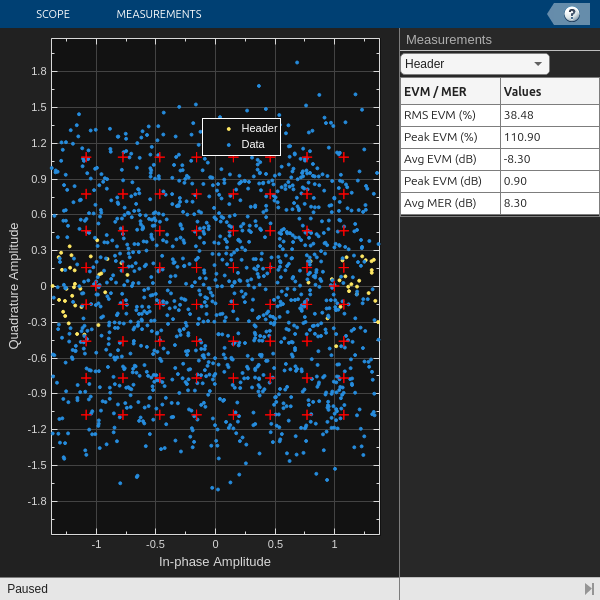

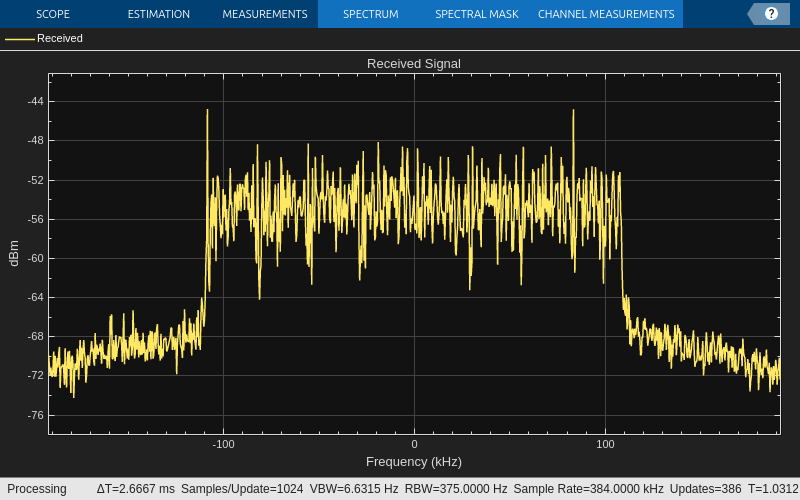

BER = 1.520558e-01 


% Clear all the function data as they contain some persistent variables
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;

errorRate = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);
BER = zeros(1,dataParams.numFrames);
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    [rxWaveform, ~, overflow] = radio();

    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals = errorRate(...
                transportBlk((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER(frameNum) = berVals(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data up to last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        else
            BER(frameNum) = 0.5;
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                 complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
    fprintf('BER = %d \n',BER(frameNum));
end

% Display the mean BER value across all frames
fprintf('Simulation complete!\nAverage BER = %d',mean(BER))

Simulation complete!
Average BER = 2.438474e-01

### SNR ESTIMATION

res = getSpectrumData(spectrumAnalyze);
freq = cell2mat(res.FrequencyVector);
spectrum = cell2mat(res.Spectrum);
fmin = -100e3;
idx = (freq >= fmin) & (freq <= fmin*(-1));
meanPowerdB = mean(spectrum(idx));
idx = find(freq == 129000);
SNRestimation = meanPowerdB - (spectrum(idx));
SNR_vect = repmat(SNRestimation, 1, dataParams.numFrames);
fprintf('SNR estimated: %d\n', SNRestimation);

SNR estimated: 1.304730e+01


release(radio);

## Troubleshooting

#### **No data in any frame**

Problem

- The receiver continuously receives no data in any frame.

Possible causes

- Transmitter is not running

- Too high or too low transmitter and receiver gains

- Too many under-runs at the transmitter

Possible solutions

- Ensure that the transmitter is running

- Adjust the transmitter and receiver gains

- Adjust the frame length to make sure there are very few under-runs at the transmitter.

#### **Header CRC fails**

Problem

- Even when synchronization and receiver camping are successful, the header CRC check fails.

Possible causes

-  Insufficient compensation of clock frequency offset.

Possible solutions

- The frequency compensation algorithm measures and corrects the frequency and phase offset for each frame, and it can estimate the correct offset up to half of the subcarrier spacing. You can calibrate the frequency offset to resolve this error.

For USRP radios, you can determine the frequency offset by sending a tone at a known frequency from the transmitter and measure the offset between the transmitted and received frequency. Apply the measured offset to the center frequency of `comm.SDRuReceiver` receiver System object.

For ADALM-Pluto radios, run the [Frequency offset calibration with ADALM-Pluto Radio in Simulink](docid:plutoradio_ug#mw_baa863fb-d239-4495-baf9-eb6864e0f592) example to get the frequency offset. Apply the measured offset to the center frequency of the `comm.SDRRxPluto`  receiver System object.

#### **Data decoding fails**

Problem

- The data decoding fails even when the header CRC decoding is successful.

Possible causes

- Data overflow at the receiver

- Inaccurate channel estimate due to exceeding frame length.

Possible solutions

-  Adjust the frame size

- Change the number of symbols per frame to minimize the frame length.